# Configure Incremental Learning Options

Prepare an incremental regression learner by specifying a metrics warm-up period, during which the `updateMetricsAndFit` function only fits the model. Specify a metrics window size of 500 observations. Train the model by using SGD, and adjust the SGD batch size, learning rate, and regularization parameter. 

Load the robot arm data set. 

%load robotarm
idxTest

idxTest =     76    48    62    28    26    47    16    99    92   106    84   119


count = length(idxTest)

count = 12


for i=1:count 
   [i idxTest(i) ryan4_battery_dataset(idxTest(i)).cycle_life ]
end

ans =      1    76   140


ans =      2    48   168


ans =      3    62   203


ans =      4    28   222


ans =      5    26   239


ans =      6    47   270


ans =      7    16   316


ans =      8    99   355


ans =      9    92   414


ans =     10   106   504


ans =     11    84   638


ans =           12         119        1019


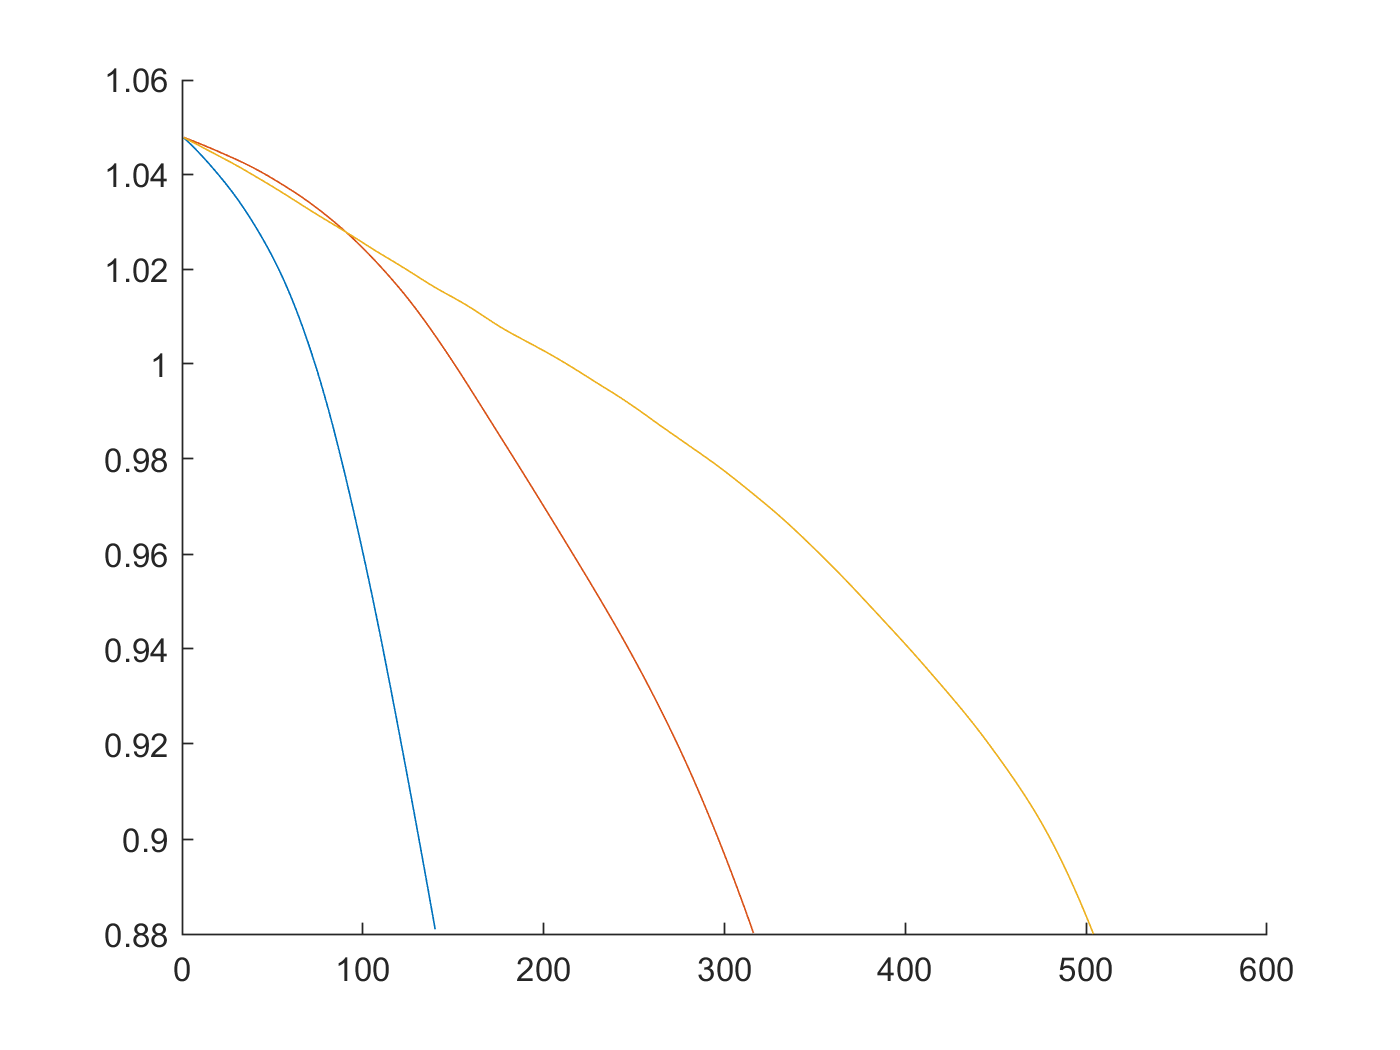


% 1 76  140 
% 7 16  316
% 10 106 504
%% 11 84 638

figure, hold on
plot( ryan4_battery_dataset(idxTest(1)).QDischargeSmooth )
plot( ryan4_battery_dataset(idxTest(7)).QDischargeSmooth )
plot( ryan4_battery_dataset(idxTest(10)).QDischargeSmooth )
hold off


Cap_change = (Cap_Rated + Cap_EOL ) / 2

Cap_change = 0.9640


[idx1change] = find(ryan4_battery_dataset(idxTest(1)).QDischargeSmooth >= Cap_change,1,'last')

idx1change = 97

[idx2change] = find(ryan4_battery_dataset(idxTest(7)).QDischargeSmooth >= Cap_change,1,'last')

idx2change = 209

[idx3change] = find(ryan4_battery_dataset(idxTest(10)).QDischargeSmooth >= Cap_change,1,'last')

idx3change = 341


ryan4_change_11Qd = ryan4_battery_dataset(idxTest(1)).QDischargeSmooth

ryan4_change_11Qd =     1.0476
    1.0473
    1.0469
    1.0465
    1.0462
    1.0458
    1.0454
    1.0450
    1.0446
    1.0442


ryan4_change_22Qd = ryan4_battery_dataset(idxTest(7)).QDischargeSmooth

ryan4_change_22Qd =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


ryan4_change_33Qd = ryan4_battery_dataset(idxTest(10)).QDischargeSmooth

ryan4_change_33Qd =     1.0477
    1.0475
    1.0473
    1.0471
    1.0469
    1.0467
    1.0465
    1.0463
    1.0461
    1.0459


ryan4_change_21Qd = [ ryan4_change_22Qd(1:idx2change) ; ryan4_change_11Qd(idx1change+1:end) ]

ryan4_change_21Qd =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


ryan4_change_23Qd = [ ryan4_change_22Qd(1:idx2change) ; ryan4_change_11Qd(idx3change+1:end) ]

ryan4_change_23Qd =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464



ryan4_change_11VdFull = ryan4_battery_dataset(idxTest(1)).Vd;
ryan4_change_22VdFull = ryan4_battery_dataset(idxTest(7)).Vd;
ryan4_change_33VdFull = ryan4_battery_dataset(idxTest(10)).Vd;
ryan4_change_21VdFull = vertcat( ryan4_change_22VdFull(1:idx2change,:) , ryan4_change_11VdFull(idx1change+1:end,:) )

ryan4_change_21VdFull =     3.3035    3.2409    3.2095    3.1927    3.1825    3.1759    3.1710    3.1672    3.1640    3.1613    3.1585    3.1562    3.1539    3.1518    3.1498    3.1475    3.1458    3.1437    3.1418    3.1397    3.1376    3.1354    3.1333    3.1313    3.1291    3.1269    3.1246    3.1223    3.1198    3.1176    3.1151    3.1125    3.1104    3.1075    3.1049    3.1024    3.0996    3.0970    3.0942    3.0914    3.0886    3.0857    3.0828    3.0799    3.0768    3.0736    3.0703    3.0671    3.0635    3.0599
    3.3032    3.2402    3.2090    3.1921    3.1820    3.1754    3.1705    3.1668    3.1635    3.1607    3.1581    3.1560    3.1536    3.1514    3.1492    3.1474    3.1453    3.1432    3.1411    3.1392    3.1371    3.1350    3.1330    3.1307    3.1285    3.1262    3.1241    3.1218    3.1195    3.1170    3.1146    3.1120    3.1096    3.1070    3.1044    3.1019    3.0993    3.0965    3.0937    3.0910    3.0879    3.0851    3.0823    3.0793    3.0764    3.0730    3.0699    3

ryan4_change_23VdFull = vertcat( ryan4_change_22VdFull(1:idx2change,:) , ryan4_change_33VdFull(idx3change+1:end,:) )

ryan4_change_23VdFull =     3.3035    3.2409    3.2095    3.1927    3.1825    3.1759    3.1710    3.1672    3.1640    3.1613    3.1585    3.1562    3.1539    3.1518    3.1498    3.1475    3.1458    3.1437    3.1418    3.1397    3.1376    3.1354    3.1333    3.1313    3.1291    3.1269    3.1246    3.1223    3.1198    3.1176    3.1151    3.1125    3.1104    3.1075    3.1049    3.1024    3.0996    3.0970    3.0942    3.0914    3.0886    3.0857    3.0828    3.0799    3.0768    3.0736    3.0703    3.0671    3.0635    3.0599
    3.3032    3.2402    3.2090    3.1921    3.1820    3.1754    3.1705    3.1668    3.1635    3.1607    3.1581    3.1560    3.1536    3.1514    3.1492    3.1474    3.1453    3.1432    3.1411    3.1392    3.1371    3.1350    3.1330    3.1307    3.1285    3.1262    3.1241    3.1218    3.1195    3.1170    3.1146    3.1120    3.1096    3.1070    3.1044    3.1019    3.0993    3.0965    3.0937    3.0910    3.0879    3.0851    3.0823    3.0793    3.0764    3.0730    3.0699    3


% https://kr.mathworks.com/matlabcentral/answers/80480-how-do-i-take-the-average-of-every-n-values-in-a-vector
blockSize = [1, 5] % 다섯개를 묶어서.

blockSize =      1     5


meanFilterFunction = @(theBlockStructure) mean2(theBlockStructure.data(:))

meanFilterFunction = function_handle with value:
    @(theBlockStructure)mean2(theBlockStructure.data(:))



ryan4_change_11Vd = blockproc(ryan4_change_11VdFull, blockSize, meanFilterFunction)

ryan4_change_11Vd =     3.2126    3.1534    3.1381    3.1265    3.1147    3.1020    3.0882    3.0731    3.0559    3.0355    3.0098    2.9756    2.9247    2.8420    2.6949    2.4128    2.0000    2.0000    2.0000    2.0000
    3.2136    3.1548    3.1397    3.1281    3.1165    3.1040    3.0906    3.0757    3.0590    3.0390    3.0144    2.9805    2.9309    2.8506    2.7076    2.4402    2.0000    2.0002    2.0003    2.0003
    3.2120    3.1531    3.1376    3.1257    3.1138    3.1014    3.0875    3.0728    3.0555    3.0355    3.0100    2.9762    2.9257    2.8437    2.6977    2.4178    2.0000    1.9999    1.9997    1.9997
    3.2123    3.1532    3.1379    3.1260    3.1141    3.1015    3.0876    3.0724    3.0553    3.0346    3.0091    2.9744    2.9228    2.8391    2.6899    2.3949    2.0000    2.0001    2.0002    2.0002
    3.2128    3.1531    3.1377    3.1256    3.1139    3.1013    3.0877    3.0731    3.0560    3.0364    3.0115    2.9780    2.9277    2.8465    2.7013    2.4262    1.9999    2.

ryan4_change_22Vd = blockproc(ryan4_change_22VdFull, blockSize, meanFilterFunction)

ryan4_change_22Vd =     3.2258    3.1679    3.1540    3.1437    3.1333    3.1222    3.1101    3.0969    3.0828    3.0669    3.0481    3.0239    2.9911    2.9419    2.8589    2.6959    2.3086    2.0000    2.0001    2.0001
    3.2253    3.1674    3.1537    3.1432    3.1329    3.1217    3.1095    3.0965    3.0822    3.0664    3.0474    3.0232    2.9902    2.9408    2.8571    2.6928    2.3031    1.9998    1.9997    1.9997
    3.2251    3.1671    3.1535    3.1430    3.1326    3.1215    3.1093    3.0962    3.0820    3.0661    3.0470    3.0229    2.9898    2.9403    2.8565    2.6916    2.3006    2.0001    2.0001    2.0001
    3.2257    3.1676    3.1538    3.1433    3.1329    3.1218    3.1097    3.0964    3.0822    3.0663    3.0473    3.0231    2.9900    2.9404    2.8562    2.6908    2.2958    1.9998    1.9999    1.9999
    3.2259    3.1678    3.1540    3.1435    3.1331    3.1219    3.1097    3.0965    3.0823    3.0665    3.0474    3.0232    2.9901    2.9403    2.8559    2.6899    2.2927    1.

ryan4_change_33Vd = blockproc(ryan4_change_33VdFull, blockSize, meanFilterFunction)

ryan4_change_33Vd =     3.2365    3.1836    3.1705    3.1604    3.1507    3.1406    3.1295    3.1175    3.1047    3.0914    3.0767    3.0599    3.0394    3.0131    2.9753    2.9079    2.7298    2.0791    2.0000    2.0000
    3.2364    3.1834    3.1703    3.1602    3.1506    3.1404    3.1294    3.1173    3.1045    3.0911    3.0765    3.0596    3.0391    3.0127    2.9747    2.9067    2.7286    2.0777    2.0000    2.0000
    3.2364    3.1832    3.1701    3.1599    3.1502    3.1401    3.1290    3.1169    3.1042    3.0908    3.0761    3.0591    3.0384    3.0119    2.9736    2.9049    2.7234    2.0741    2.0000    2.0000
    3.2360    3.1828    3.1696    3.1595    3.1498    3.1396    3.1285    3.1164    3.1036    3.0902    3.0754    3.0584    3.0376    3.0109    2.9722    2.9027    2.7190    2.0726    2.0000    2.0000
    3.2358    3.1825    3.1694    3.1592    3.1495    3.1394    3.1283    3.1162    3.1034    3.0899    3.0752    3.0581    3.0373    3.0105    2.9717    2.9019    2.7165    2.

ryan4_change_21Vd = blockproc(ryan4_change_21VdFull, blockSize, meanFilterFunction)

ryan4_change_21Vd =     3.2258    3.1679    3.1540    3.1437    3.1333    3.1222    3.1101    3.0969    3.0828    3.0669    3.0481    3.0239    2.9911    2.9419    2.8589    2.6959    2.3086    2.0000    2.0001    2.0001
    3.2253    3.1674    3.1537    3.1432    3.1329    3.1217    3.1095    3.0965    3.0822    3.0664    3.0474    3.0232    2.9902    2.9408    2.8571    2.6928    2.3031    1.9998    1.9997    1.9997
    3.2251    3.1671    3.1535    3.1430    3.1326    3.1215    3.1093    3.0962    3.0820    3.0661    3.0470    3.0229    2.9898    2.9403    2.8565    2.6916    2.3006    2.0001    2.0001    2.0001
    3.2257    3.1676    3.1538    3.1433    3.1329    3.1218    3.1097    3.0964    3.0822    3.0663    3.0473    3.0231    2.9900    2.9404    2.8562    2.6908    2.2958    1.9998    1.9999    1.9999
    3.2259    3.1678    3.1540    3.1435    3.1331    3.1219    3.1097    3.0965    3.0823    3.0665    3.0474    3.0232    2.9901    2.9403    2.8559    2.6899    2.2927    1.

ryan4_change_23Vd = blockproc(ryan4_change_23VdFull, blockSize, meanFilterFunction)

ryan4_change_23Vd =     3.2258    3.1679    3.1540    3.1437    3.1333    3.1222    3.1101    3.0969    3.0828    3.0669    3.0481    3.0239    2.9911    2.9419    2.8589    2.6959    2.3086    2.0000    2.0001    2.0001
    3.2253    3.1674    3.1537    3.1432    3.1329    3.1217    3.1095    3.0965    3.0822    3.0664    3.0474    3.0232    2.9902    2.9408    2.8571    2.6928    2.3031    1.9998    1.9997    1.9997
    3.2251    3.1671    3.1535    3.1430    3.1326    3.1215    3.1093    3.0962    3.0820    3.0661    3.0470    3.0229    2.9898    2.9403    2.8565    2.6916    2.3006    2.0001    2.0001    2.0001
    3.2257    3.1676    3.1538    3.1433    3.1329    3.1218    3.1097    3.0964    3.0822    3.0663    3.0473    3.0231    2.9900    2.9404    2.8562    2.6908    2.2958    1.9998    1.9999    1.9999
    3.2259    3.1678    3.1540    3.1435    3.1331    3.1219    3.1097    3.0965    3.0823    3.0665    3.0474    3.0232    2.9901    2.9403    2.8559    2.6899    2.2927    1.



ryan4_change_11Rul = linspace(ryan4_battery_dataset(idxTest(1)).cycle_life,1,ryan4_battery_dataset(idxTest(1)).cycle_life)'

ryan4_change_11Rul =    140
   139
   138
   137
   136
   135
   134
   133
   132
   131


ryan4_change_22Rul = linspace(ryan4_battery_dataset(idxTest(7)).cycle_life,1,ryan4_battery_dataset(idxTest(7)).cycle_life)'

ryan4_change_22Rul =    316
   315
   314
   313
   312
   311
   310
   309
   308
   307


ryan4_change_33Rul = linspace(ryan4_battery_dataset(idxTest(10)).cycle_life,1,ryan4_battery_dataset(idxTest(10)).cycle_life)'

ryan4_change_33Rul =    504
   503
   502
   501
   500
   499
   498
   497
   496
   495


ryan4_change_21Rul = linspace(length(ryan4_change_21Qd),1,length(ryan4_change_21Qd))'

ryan4_change_21Rul =    252
   251
   250
   249
   248
   247
   246
   245
   244
   243


ryan4_change_23Rul = linspace(length(ryan4_change_23Qd),1,length(ryan4_change_23Qd))'

ryan4_change_23Rul =    209
   208
   207
   206
   205
   204
   203
   202
   201
   200


% [ynorm_ryan4_change_21Rul,ymax_ryan4_change_21Rul,ymin_ryan4_change_21Rul,yrate_ryan4_change_21Rul] = minmax_norm_x(ryan4_change_21Rul);
% [ynorm_ryan4_change_22Rul,ymax_ryan4_change_22Rul,ymin_ryan4_change_22Rul,yrate_ryan4_change_22Rul] = minmax_norm_x(ryan4_change_22Rul);
% [ynorm_ryan4_change_23Rul,ymax_ryan4_change_23Rul,ymin_ryan4_change_23Rul,yrate_ryan4_change_23Rul] = minmax_norm_x(ryan4_change_23Rul);
% 
% [ynorm_ryan4_change_21Qd,ymax_ryan4_change_21Qd,ymin_ryan4_change_21Qd,yrate_ryan4_change_21Qd] = minmax_norm_x(ryan4_change_21Qd);
% [ynorm_ryan4_change_22Qd,ymax_ryan4_change_22Qd,ymin_ryan4_change_22Qd,yrate_ryan4_change_22Qd] = minmax_norm_x(ryan4_change_22Qd);
% [ynorm_ryan4_change_23Qd,ymax_ryan4_change_23Qd,ymin_ryan4_change_23Qd,yrate_ryan4_change_23Qd] = minmax_norm_x(ryan4_change_23Qd);
% 
% [xnorm_ryan4_change_21Vd,xmax_ryan4_change_21Vd,xmin_ryan4_change_21Vd,xrate_ryan4_change_21Vd] = minmax_norm_x(ryan4_change_21Vd);
% [xnorm_ryan4_change_22Vd,xmax_ryan4_change_22Vd,xmin_ryan4_change_22Vd,xrate_ryan4_change_22Vd] = minmax_norm_x(ryan4_change_22Vd);
% [xnorm_ryan4_change_23Vd,xmax_ryan4_change_23Vd,xmin_ryan4_change_23Vd,xrate_ryan4_change_23Vd] = minmax_norm_x(ryan4_change_23Vd);


ynorm_ryan4_change_21Rul = minmax_norm_x_with_param(ryan4_change_21Rul  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_21Rul =     0.2145
    0.2137
    0.2128
    0.2120
    0.2111
    0.2103
    0.2094
    0.2085
    0.2077
    0.2068


ynorm_ryan4_change_22Rul = minmax_norm_x_with_param(ryan4_change_22Rul  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_22Rul =     0.2692
    0.2684
    0.2675
    0.2667
    0.2658
    0.2650
    0.2641
    0.2632
    0.2624
    0.2615


ynorm_ryan4_change_23Rul = minmax_norm_x_with_param(ryan4_change_23Rul  , ymin_RUL , yrate_RUL )

ynorm_ryan4_change_23Rul =     0.1778
    0.1769
    0.1761
    0.1752
    0.1744
    0.1735
    0.1726
    0.1718
    0.1709
    0.1701


ynorm_ryan4_change_21Qd  = minmax_norm_x_with_param(ryan4_change_21Qd   , ymin_SOH , yrate_SOH )

ynorm_ryan4_change_21Qd =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


ynorm_ryan4_change_22Qd  = minmax_norm_x_with_param(ryan4_change_22Qd   , ymin_SOH , yrate_SOH )

ynorm_ryan4_change_22Qd =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


ynorm_ryan4_change_23Qd  = minmax_norm_x_with_param(ryan4_change_23Qd   , ymin_SOH , yrate_SOH )

ynorm_ryan4_change_23Qd =     0.9869
    0.9861
    0.9852
    0.9843
    0.9835
    0.9826
    0.9817
    0.9809
    0.9800
    0.9791


xnorm_ryan4_change_21Vd  = minmax_norm_x_with_param(ryan4_change_21Vd   , xmin_Vd  , xrate_Vd  )

xnorm_ryan4_change_21Vd =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209

xnorm_ryan4_change_22Vd  = minmax_norm_x_with_param(ryan4_change_22Vd   , xmin_Vd  , xrate_Vd  )

xnorm_ryan4_change_22Vd =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209

xnorm_ryan4_change_23Vd  = minmax_norm_x_with_param(ryan4_change_23Vd   , xmin_Vd  , xrate_Vd  )

xnorm_ryan4_change_23Vd =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209


ytrain = ynorm_ryan4_change_21Rul

ytrain =     0.2145
    0.2137
    0.2128
    0.2120
    0.2111
    0.2103
    0.2094
    0.2085
    0.2077
    0.2068


Xtrain = xnorm_ryan4_change_21Vd

Xtrain =     0.9222    0.8786    0.8682    0.8605    0.8527    0.8443    0.8352    0.8253    0.8147    0.8028    0.7886    0.7704    0.7458    0.7088    0.6464    0.5239    0.2329    0.0010    0.0011    0.0011
    0.9218    0.8783    0.8680    0.8601    0.8523    0.8440    0.8348    0.8250    0.8143    0.8024    0.7881    0.7699    0.7451    0.7080    0.6451    0.5216    0.2288    0.0009    0.0008    0.0008
    0.9217    0.8781    0.8678    0.8599    0.8521    0.8438    0.8346    0.8247    0.8141    0.8022    0.7878    0.7697    0.7448    0.7076    0.6446    0.5207    0.2269    0.0011    0.0011    0.0011
    0.9221    0.8784    0.8680    0.8602    0.8524    0.8440    0.8349    0.8249    0.8142    0.8023    0.7880    0.7698    0.7449    0.7077    0.6444    0.5201    0.2233    0.0009    0.0009    0.0009
    0.9222    0.8786    0.8682    0.8603    0.8525    0.8441    0.8349    0.8250    0.8143    0.8025    0.7881    0.7699    0.7450    0.7076    0.6442    0.5194    0.2209    0.0010    0.0


Y_test_RUL_test1 = ryan4_change_21Rul 

Y_test_RUL_test1 =    252
   251
   250
   249
   248
   247
   246
   245
   244
   243


Y_test_SOH_test1 = ryan4_change_21Qd

Y_test_SOH_test1 =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464



RUL_test = ryan4_change_21Rul

RUL_test =    252
   251
   250
   249
   248
   247
   246
   245
   244
   243


SOH_test = ryan4_change_21Qd

SOH_test =     1.0477
    1.0476
    1.0474
    1.0473
    1.0471
    1.0470
    1.0468
    1.0467
    1.0465
    1.0464


% Yfit_test_RUL_test1 = Yfit_test_RUL(idxFindAll);


compareTo = Y_test_RUL_test1(idx1change+1)

compareTo = 155


count = length(idxTrain) + length(idxValid)

count = 107

idxSel = 0;
diff = 1000;
for i=1:count 
    [val,idxCross] = min(abs(ryan4_battery_dataset(idxTrainValid(i)).QDischarge -  Cap_change ));
    rul_remained =  ryan4_battery_dataset(idxTrainValid(i)).cycle_life - idxCross ;
    diff_new = abs( rul_remained - compareTo );
    if diff_new < diff 
        idxSel = idxTrainValid(i);
        diff = diff_new;
        idxCrossSel = idxCross;
    end
end



inTrain = any(idxTrain==idxSel)

inTrain = logical
   0



if inTrain
    idxFindSel = idxTest(find(idxTest == idxTestSort(idxSearch)));
    idxFindAllSel = find(idxTestAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
else
    idxFindSel = idxTest(find(idxValid == idxValidSort(idxSearch)));
    idxFindAllSel = find(idxValidAll_batIndex == idxFindSel);
    y_test_RUL_Sel1 = y_test_RUL(idxFindAllSel);
    Y_test_RUL_Sel1 = Y_test_RUL(idxFindAllSel);
    Y_test_SOH_Sel1 = Y_test_SOH(idxFindAllSel); 
end 


ytrainSim = y_test_RUL_Sel1(idxCrossSel:end);

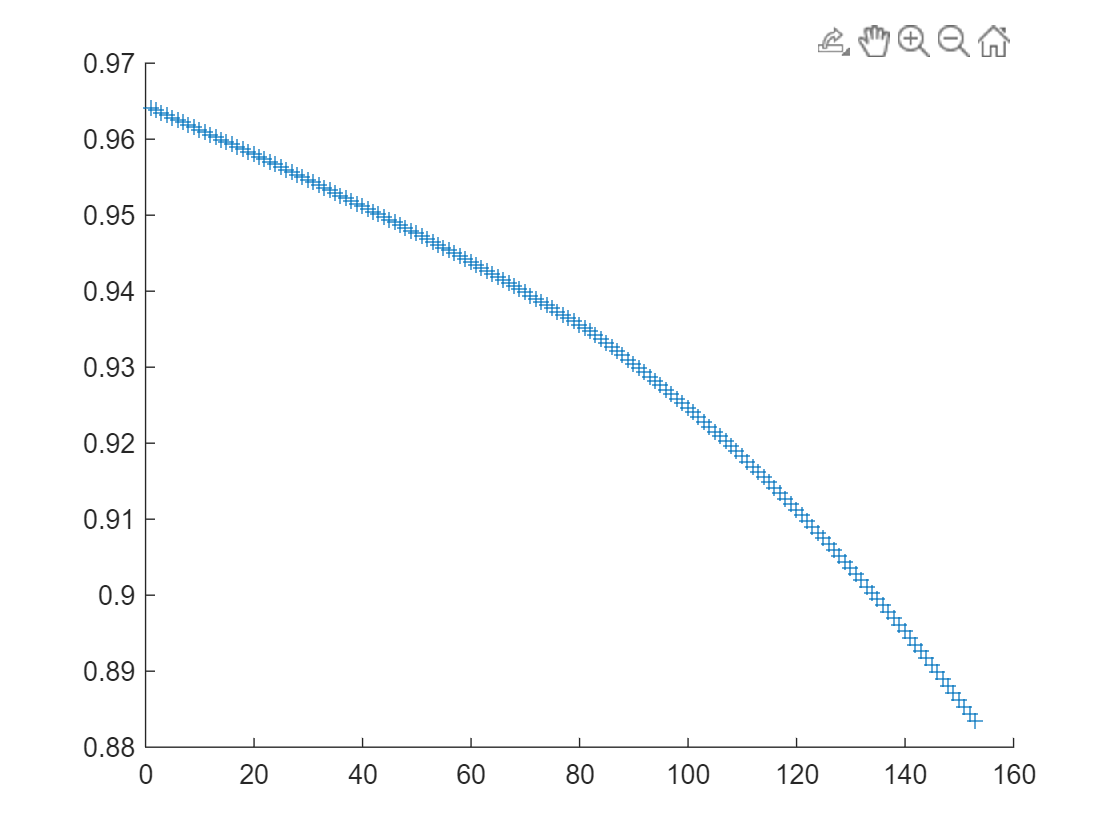


figure, hold on
plot(Y_test_SOH_test1(idxCross:end),'x')
plot(ryan4_battery_dataset(idxSel).QDischargeSmooth(idxCrossSel:end),'+')
hold off

n = numel(ytrain);

For details on the data set, enter  `Description` at the command line.

Create an incremental linear model for regression. Configure the model as follows:

- Specify the SGD solver.

- Assume that these settings work well for the problem: a ridge regularization parameter value of 0.001, SGD batch size of 20, learning rate of 0.002, and half the width of the epsilon insensitive band for SVM of 0.05.

- Specify that the incremental fitting functions process the raw (unstandardized) predictor data.

- Specify a metrics warm-up period of 1000 observations.

- Specify a metrics window size of 500 observations.

- Track the epsilon insensitive loss, MSE, and mean absolute error (MAE) to measure the performance of the model. The software supports epsilon insensitive loss and MSE. Create an anonymous function that measures the absolute error of each new observation. Create a structure array containing the name `MeanAbsoluteError` and its corresponding function.

maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

Mdl = incrementalRegressionLinear(  ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',10, ...
    'Learner','leastsquares', ...
    'Metrics',{ 'mse' maemetric})

Mdl =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [2×2 table]
    ResponseTransform: 'none'
                 Beta: [0×1 double]
                 Bias: 0
              Learner: 'leastsquares'


  Properties, Methods


`Mdl` is an `incrementalRegressionLinear` model object configured for incremental learning without an estimation period.

Fit the incremental model to the data by using the `updateMetricsAndFit` function. At each iteration:

- Simulate a data stream by processing a chunk of 50 observations. Note that the chunk size is different from SGD batch size.

- Overwrite the previous incremental model with a new one fitted to the incoming observations.

- Store the estimated coefficient $\beta_{10}$, the cumulative metrics, and the window metrics to see how they evolve during incremental learning.

% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    

% Incremental fitting
rng("default"); % For reproducibility
for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend    ;
    Mdl = updateMetricsAndFit(Mdl,Xtrain(idx,:),ytrain(idx));
    Mdl.Beta;
    Mdl.Bias;
    %ei{j,:} = Mdl.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = Mdl.Metrics{"MeanSquaredError",:};
    mae{j,:} = Mdl.Metrics{"MeanAbsoluteError",:};
    %beta10(j + 1) = Mdl.Beta(10);
    beta10(j + 1) = Mdl.Beta(4);
end

`Mdl` is an `incrementalRegressionLinear` model object trained on all the data in the stream. During incremental learning and after the model is warmed up, `updateMetricsAndFit` checks the performance of the model on the incoming observations, and then fits the model to those observations.

To see how the performance metrics and $\beta_{10}$ evolve during training, plot them on separate tiles.

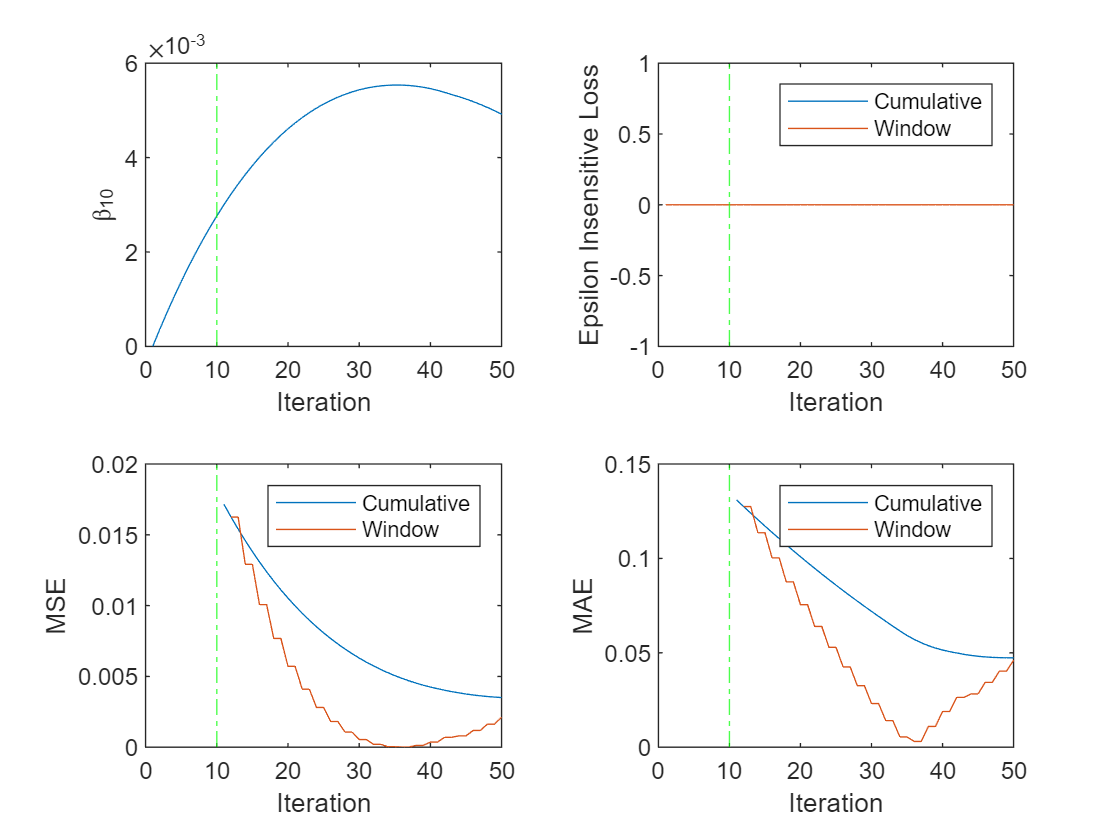

tiledlayout(2,2)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
nexttile
h = plot(ei.Variables);
xlim([0 nchunk])
ylabel('Epsilon Insensitive Loss')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,ei.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mae.Variables);
xlim([0 nchunk])
ylabel('MAE')
xline(Mdl.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mae.Properties.VariableNames)
xlabel('Iteration')

The plot suggests that `updateMetricsAndFit` does the following:

- Fit $\beta_{10}$ during all incremental learning iterations.

- Compute the performance metrics after the metrics warm-up period only.

- Compute the cumulative metrics during each iteration.

- Compute the window metrics after processing 500 observations (10 iterations).

*Copyright 2020 The MathWorks, Inc.*

total = length(ytrain)

total = 252

pre = 50;
future = total - pre

future = 202

Xtrain_all = Xtrain ;
ytrain_all = ytrain ;
Ytrain_all = RUL_test;
Ytrain_SOH_all = SOH_test;

Xtrain_pre = Xtrain(1:pre,:);
ytrain_pre = ytrain(1:pre,:);
Ytrain_pre = RUL_test(1:pre,:);
Ytrain_SOH_pre = SOH_test(1:pre,:);

Xtrain_future = Xtrain(pre+1:end,:);
ytrain_future = ytrain(pre+1:end,:);
Ytrain_future = RUL_test(pre+1:end,:);
Ytrain_SOH_future = SOH_test(pre+1:end,:);

[Mdl1,FitInfo] = fitrlinear(Xtrain_pre,ytrain_pre,"learner","leastsquares")

Mdl1 =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: 0.1823
               Lambda: 0.0200
              Learner: 'leastsquares'


  Properties, Methods


FitInfo = struct with fields:
                    Lambda: 0.0200
                 Objective: 7.4159e-05
            IterationLimit: 1000
             NumIterations: 21
              GradientNorm: 1.2993e-06
         GradientTolerance: 1.0000e-06
      RelativeChangeInBeta: 9.6952e-05
             BetaTolerance: 1.0000e-04
             DeltaGradient: []
    DeltaGradientTolerance: []
           TerminationCode: 1
         TerminationStatus: {'Tolerance on coefficients satisfied.'}
                   History: []
                   FitTime: 0.0011
                    Solver: {'bfgs'}


Mdl1.Beta

ans =    -0.0001
    0.0001
    0.0001
    0.0002
    0.0002
    0.0002
    0.0003
    0.0003
    0.0003
    0.0004


Mdl1.Bias

ans = 0.1823

yhat_pre_calc = Xtrain_pre(1,:) * Mdl1.Beta + Mdl1.Bias

yhat_pre_calc = 0.1941

yhat_pre_predict = predict(Mdl1,Xtrain_pre(1,:))

yhat_pre_predict = 0.1941

# 현재까지 학습된 자신의 모델로 과거값을 예측하면 오차가 작다. 그러나 정확하지는 않다.

yhat_pre = predict(Mdl1,Xtrain_pre);


Yhat_pre = yhat_pre * yrate_RUL + ymin_RUL;

rmse_pre = sqrt( mean((Ytrain_pre - Yhat_pre).^2 ) )

rmse_pre = 14.0719

diff_percentage_pre = abs(Ytrain_pre - Yhat_pre)./Ytrain_pre.*100

diff_percentage_pre =     9.4883
    9.1597
    8.8104
    8.4660
    8.1118
    7.7477
    7.3813
    7.0101
    6.6491
    6.2791


diff_percentage_avg_pre = mean(diff_percentage_pre,1)

diff_percentage_avg_pre = 5.3963

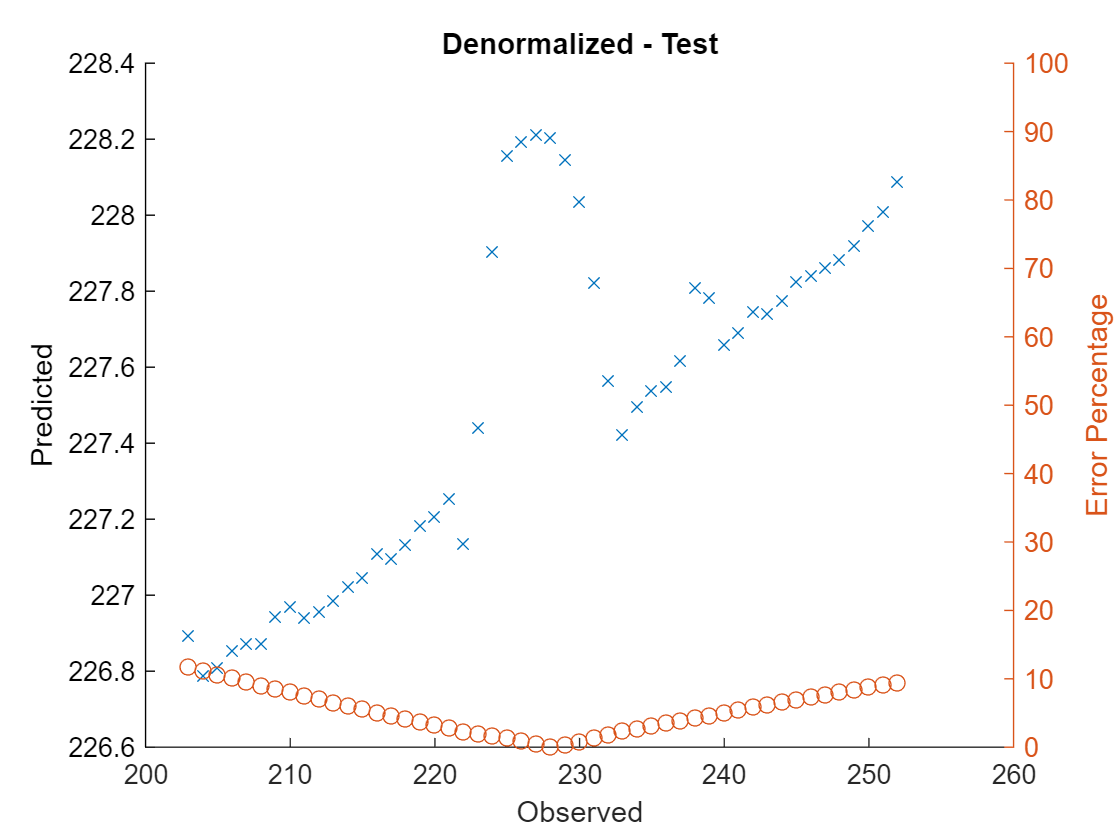

figure
hold on
%plot(Ytrain_pre,Ytrain_pre)
plot(Ytrain_pre,Yhat_pre,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_pre,diff_percentage_pre,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

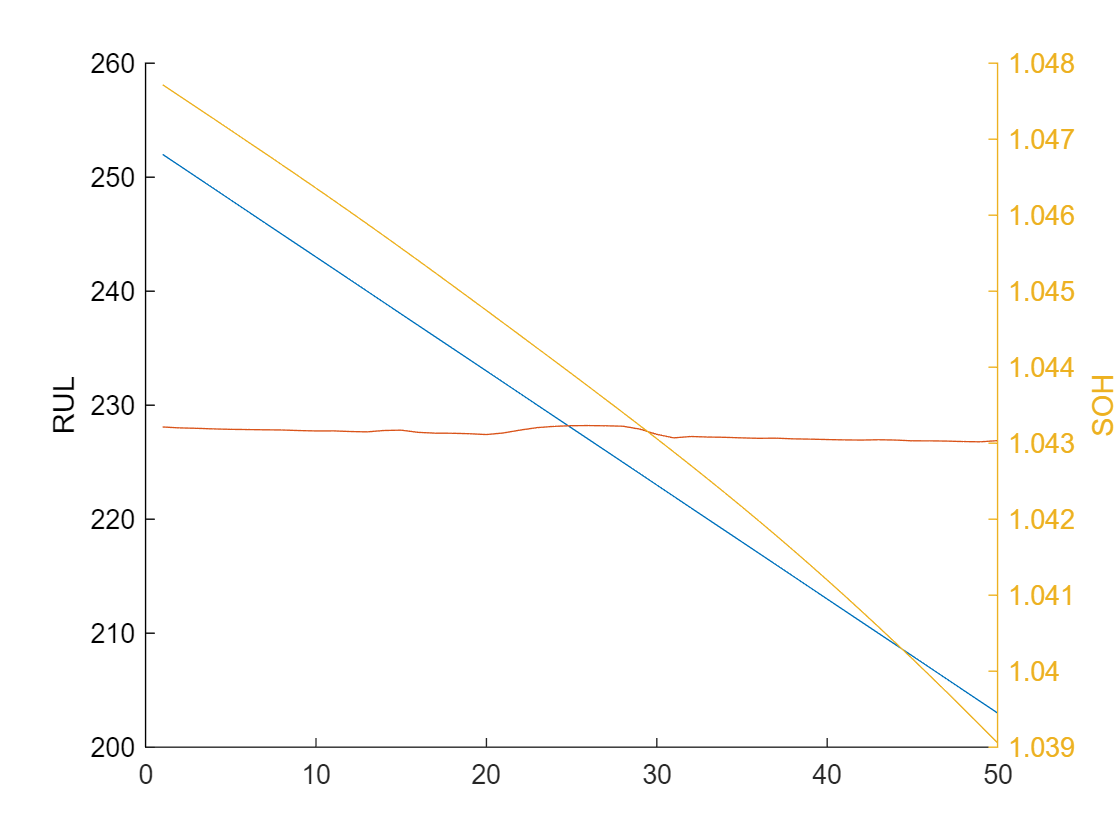


figure, hold on
plot(Ytrain_pre)
plot(Yhat_pre)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Ytrain_SOH_pre)
hold off

# 현재까지 학습된 자신의 모델로 미래를 예측하면 예측오차가 매우 커진다.

yhat_future = predict(Mdl1,Xtrain_future);
Yhat_future = yhat_future*yrate_RUL + ymin_RUL;
rmse_future = sqrt( mean((Ytrain_future - Yhat_future).^2 ) )

rmse_future = 132.7489

diff_percentage_future = abs(Ytrain_future - Yhat_future)./Ytrain_future.*100

diff_percentage_future = 1.0e+04 *

    0.0012
    0.0013
    0.0014
    0.0014
    0.0015
    0.0015
    0.0016
    0.0016
    0.0017
    0.0017


diff_percentage_avg_future = mean(diff_percentage_future,1)

diff_percentage_avg_future = 537.3311

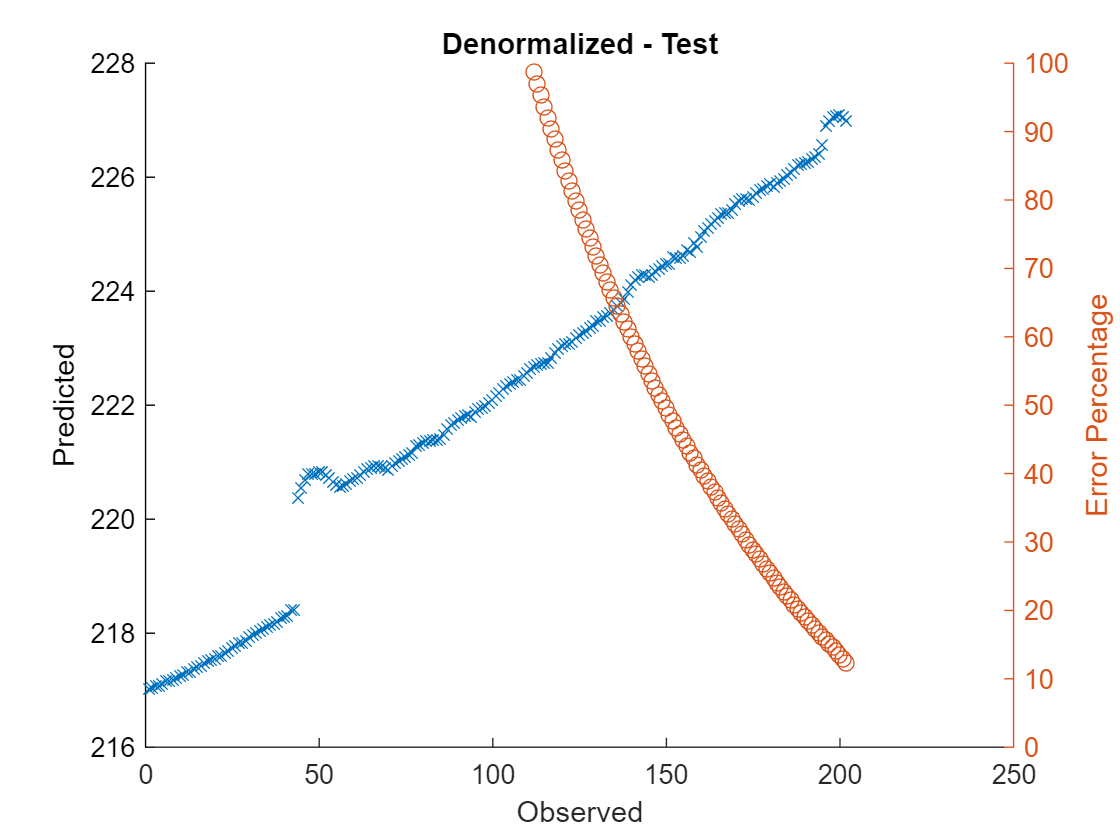

figure
hold on
%plot(Ytrain_future,Ytrain_future)
plot(Ytrain_future,Yhat_future,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_future,diff_percentage_future,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

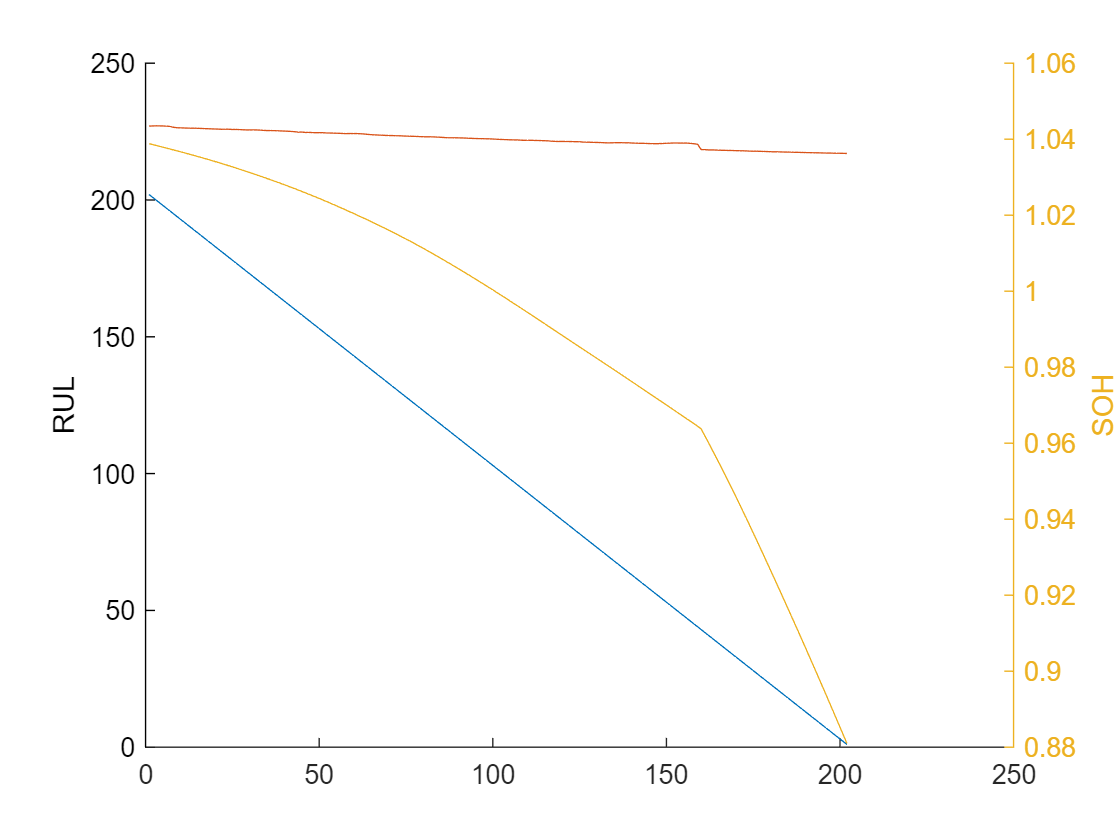


figure, hold on
plot(Ytrain_future)
plot(Yhat_future)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Ytrain_SOH_future)
hold off

# 클라우드에서 현재까지 학습된 모델로 자신을 예측하면 예측오차가 매우 좀 더 작아지지만, 자신의 데이타로 학습한 만큼의 결과가 나오지 않는다.

load('ryan4_model_RUL.mat', 'mdl_Linear_VdRul_fitrlinear')


yhat_all = predict(mdl_Linear_VdRul_fitrlinear,Xtrain_all);
Yhat_all = yhat_all * yrate_RUL + ymin_RUL;

rmse_all = sqrt( mean((Ytrain_all - Yhat_all).^2 ) )

rmse_all = 105.7268

diff_percentage_all = abs(Ytrain_all - Yhat_all)./Ytrain_all.*100

diff_percentage_all =    79.7775
   78.3592
   77.8800
   76.9676
   76.5527
   76.7339
   76.6878
   77.0879
   76.3117
   75.8005


diff_percentage_avg_all = mean(diff_percentage_all,1)

diff_percentage_avg_all = 74.6729

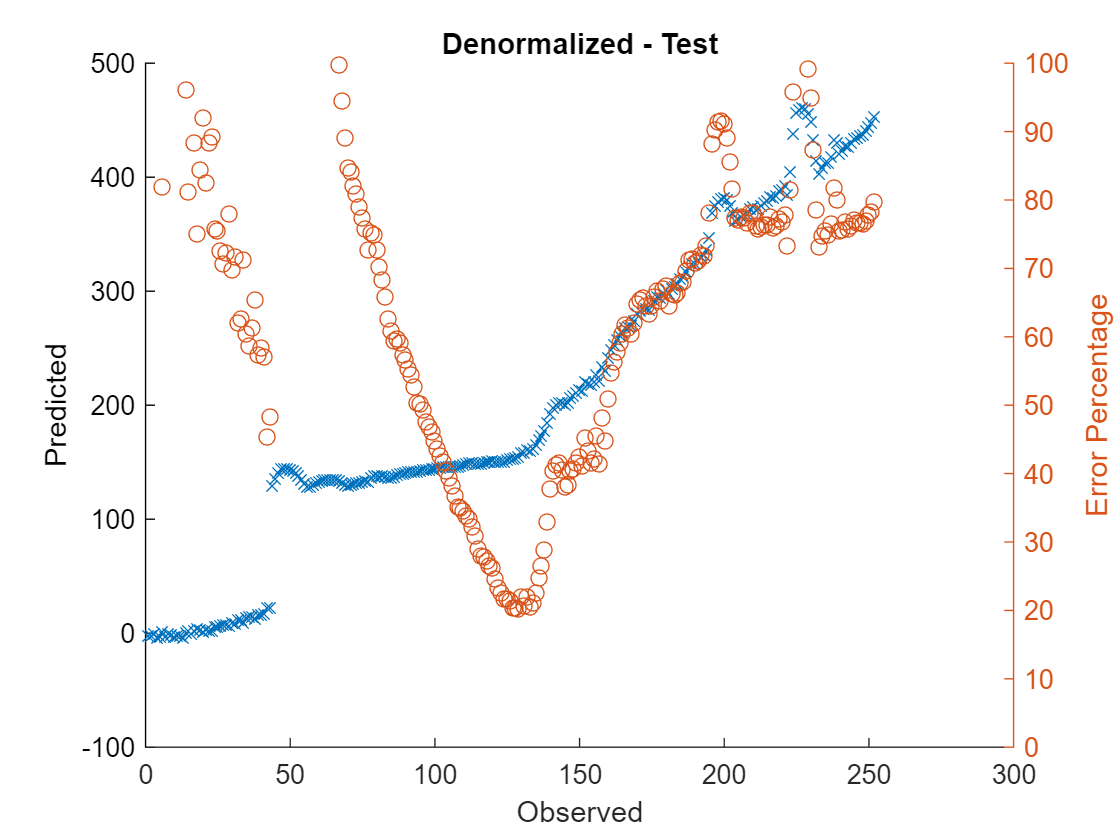

figure
hold on
plot(Ytrain_all,Yhat_all,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_all,diff_percentage_all,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

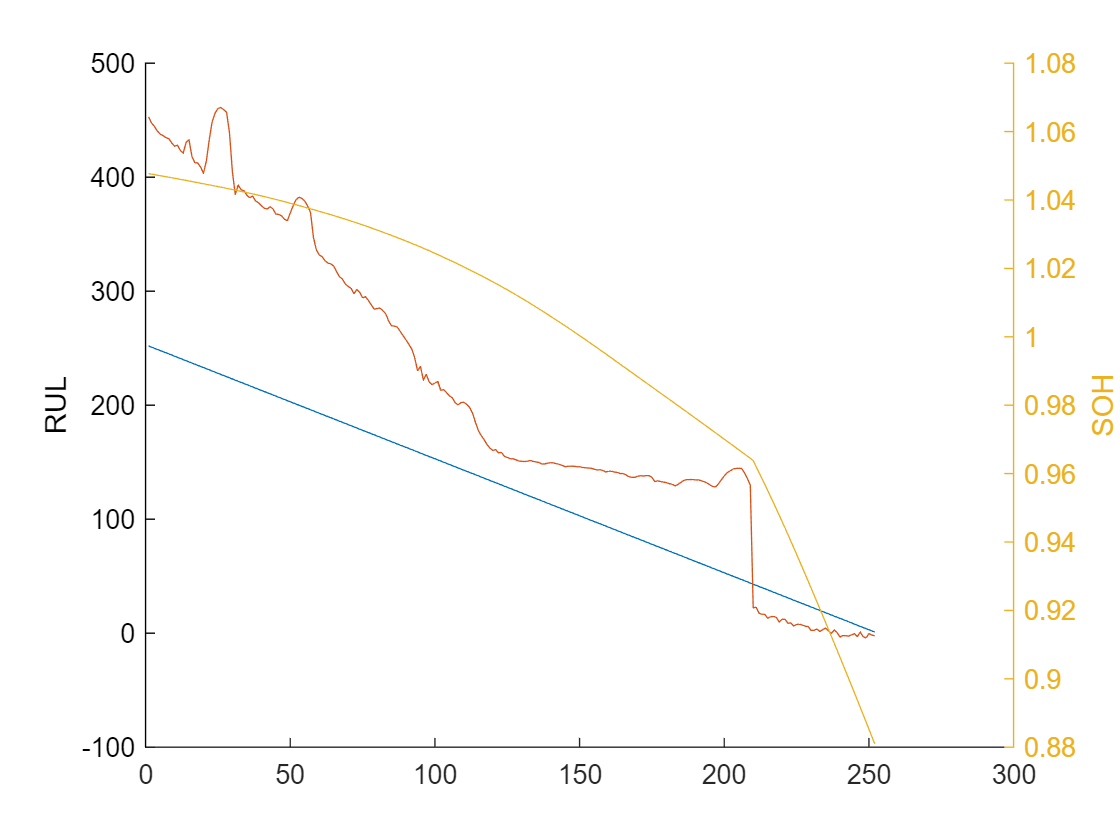



figure, hold on
plot(Y_test_RUL_test1)
plot(Yhat_all)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

yhat = predict(mdl_Linear_VdRul_fitrlinear,Xtrain(1,:))

yhat = 0.3864

mdl_Linear_VdRul_fitrlinear.Beta 

ans = 20×1
   -0.4300
   -0.2471
   -0.0565
    0.0360
    0.1613
    0.3305
    0.4949
    0.5662
    0.4575
    0.2428


mdl_Linear_VdRul_fitrlinear.Bias

ans = -1.0687

yhat_cals = Xtrain(1,:) * mdl_Linear_VdRul_fitrlinear.Beta  +  mdl_Linear_VdRul_fitrlinear.Bias

yhat_cals = 0.3864

## 점진적 학습 - 과거데이타에서 정확한 RUL 안다고 가정하면 러닝레이트를 높이자.


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' maemetric})

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' maemetric}...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc

mdl_Linear_VdRul_fitrlinear_inc =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [2×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc.Beta'

ans =    -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


for j = 1:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend   
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc = updateMetricsAndFit(...
        mdl_Linear_VdRul_fitrlinear_inc,...
        Xtrain(idx,:),...
        ytrain(idx));
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc.Beta'
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp]
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"MeanSquaredError",:};
    mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc.Beta(10);
end

idx =      1     2     3     4     5


ans =    -0.4453   -0.2617   -0.0709    0.0217    0.1471    0.3164    0.4810    0.5524    0.4439    0.2294    0.0372   -0.1052   -0.0895   -0.0152    0.1290   -0.0404    1.0280    0.2708   -0.4946   -0.4823


ans =     0.2145    0.1988    0.0157
    0.2137    0.1944    0.0193
    0.2128    0.1919    0.0209
    0.2120    0.1884    0.0235
    0.2111    0.1860    0.0251


idx =      6     7     8     9    10


ans =    -0.4428   -0.2593   -0.0686    0.0240    0.1494    0.3186    0.4832    0.5546    0.4461    0.2315    0.0393   -0.1031   -0.0875   -0.0133    0.1308   -0.0390    1.0284    0.2708   -0.4946   -0.4823


ans =     0.2103    0.2151   -0.0049
    0.2094    0.2135   -0.0041
    0.2085    0.2129   -0.0044
    0.2077    0.2098   -0.0021
    0.2068    0.2073   -0.0004


idx =     11    12    13    14    15


ans =    -0.4430   -0.2596   -0.0688    0.0237    0.1491    0.3184    0.4829    0.5543    0.4458    0.2313    0.0391   -0.1033   -0.0877   -0.0135    0.1306   -0.0391    1.0283    0.2708   -0.4945   -0.4822


ans =     0.2060    0.2046    0.0014
    0.2051    0.2006    0.0045
    0.2043    0.1986    0.0056
    0.2034    0.2065   -0.0031
    0.2026    0.2085   -0.0059


idx =     16    17    18    19    20


ans =    -0.4420   -0.2587   -0.0680    0.0246    0.1500    0.3192    0.4837    0.5550    0.4465    0.2320    0.0399   -0.1025   -0.0870   -0.0128    0.1312   -0.0386    1.0284    0.2708   -0.4945   -0.4822


ans =     0.2017    0.2070   -0.0053
    0.2009    0.2024   -0.0015
    0.2000    0.2021   -0.0021
    0.1991    0.1991    0.0000
    0.1983    0.1946    0.0037


idx =     21    22    23    24    25


ans =    -0.4449   -0.2614   -0.0707    0.0219    0.1473    0.3165    0.4810    0.5524    0.4439    0.2295    0.0374   -0.1049   -0.0893   -0.0150    0.1291   -0.0403    1.0275    0.2707   -0.4944   -0.4821


ans =     0.1974    0.1681    0.0293
    0.1966    0.1835    0.0131
    0.1957    0.1966   -0.0009
    0.1949    0.2029   -0.0080
    0.1940    0.2064   -0.0124


idx =     26    27    28    29    30


ans =    -0.4450   -0.2615   -0.0708    0.0218    0.1471    0.3163    0.4808    0.5522    0.4438    0.2294    0.0373   -0.1050   -0.0894   -0.0151    0.1290   -0.0403    1.0274    0.2707   -0.4944   -0.4821


ans =     0.1932    0.2053   -0.0121
    0.1923    0.2037   -0.0114
    0.1915    0.2017   -0.0102
    0.1906    0.1867    0.0039
    0.1897    0.1583    0.0315


idx =     31    32    33    34    35


ans =    -0.4410   -0.2577   -0.0671    0.0254    0.1508    0.3199    0.4844    0.5557    0.4472    0.2328    0.0406   -0.1017   -0.0862   -0.0121    0.1317   -0.0382    1.0281    0.2707   -0.4943   -0.4820


ans =     0.1889    0.1893   -0.0004
    0.1880    0.1965   -0.0084
    0.1872    0.1930   -0.0059
    0.1863    0.1923   -0.0059
    0.1855    0.1889   -0.0034


idx =     36    37    38    39    40


ans =    -0.4411   -0.2579   -0.0673    0.0253    0.1506    0.3197    0.4841    0.5555    0.4470    0.2326    0.0405   -0.1019   -0.0864   -0.0123    0.1316   -0.0383    1.0279    0.2706   -0.4943   -0.4820


ans =     0.1846    0.1846    0.0000
    0.1838    0.1859   -0.0022
    0.1829    0.1823    0.0006
    0.1821    0.1810    0.0010
    0.1812    0.1789    0.0023


idx =     41    42    43    44    45


ans =    -0.4408   -0.2576   -0.0670    0.0255    0.1508    0.3199    0.4843    0.5556    0.4472    0.2327    0.0407   -0.1017   -0.0862   -0.0121    0.1317   -0.0382    1.0279    0.2706   -0.4942   -0.4819


ans =     0.1803    0.1797    0.0007
    0.1795    0.1791    0.0004
    0.1786    0.1807   -0.0021
    0.1778    0.1792   -0.0015
    0.1769    0.1753    0.0016


idx =     46    47    48    49    50


ans =    -0.4407   -0.2575   -0.0669    0.0256    0.1508    0.3199    0.4843    0.5556    0.4472    0.2328    0.0407   -0.1016   -0.0861   -0.0120    0.1318   -0.0381    1.0278    0.2706   -0.4942   -0.4819


ans =     0.1761    0.1761    0.0000
    0.1752    0.1748    0.0005
    0.1744    0.1724    0.0019
    0.1735    0.1714    0.0021
    0.1726    0.1771   -0.0044


idx =     51    52    53    54    55


ans =    -0.4421   -0.2589   -0.0683    0.0242    0.1495    0.3186    0.4830    0.5543    0.4459    0.2315    0.0395   -0.1028   -0.0873   -0.0131    0.1307   -0.0389    1.0274    0.2706   -0.4941   -0.4818


ans =     0.1718    0.1644    0.0074
    0.1709    0.1685    0.0024
    0.1701    0.1703   -0.0002
    0.1692    0.1695   -0.0002
    0.1684    0.1676    0.0008


idx =     56    57    58    59    60


ans =    -0.4402   -0.2570   -0.0665    0.0260    0.1512    0.3203    0.4846    0.5559    0.4475    0.2332    0.0411   -0.1012   -0.0857   -0.0117    0.1320   -0.0379    1.0276    0.2705   -0.4941   -0.4818


ans =     0.1675    0.1872   -0.0196
    0.1667    0.1822   -0.0155
    0.1658    0.1643    0.0015
    0.1650    0.1551    0.0099
    0.1641    0.1512    0.0129


idx =     61    62    63    64    65


ans =    -0.4387   -0.2556   -0.0651    0.0273    0.1525    0.3216    0.4859    0.5572    0.4487    0.2344    0.0423   -0.1000   -0.0846   -0.0106    0.1330   -0.0372    1.0277    0.2705   -0.4940   -0.4817


ans =     0.1632    0.1671   -0.0038
    0.1624    0.1641   -0.0017
    0.1615    0.1623   -0.0008
    0.1607    0.1617   -0.0010
    0.1598    0.1601   -0.0003


idx =     66    67    68    69    70


ans =    -0.4380   -0.2550   -0.0645    0.0279    0.1531    0.3221    0.4864    0.5577    0.4493    0.2349    0.0429   -0.0995   -0.0840   -0.0101    0.1334   -0.0368    1.0277    0.2705   -0.4940   -0.4817


ans =     0.1590    0.1638   -0.0048
    0.1581    0.1599   -0.0018
    0.1573    0.1583   -0.0010
    0.1564    0.1546    0.0018
    0.1556    0.1528    0.0028


idx =     71    72    73    74    75


ans =    -0.4375   -0.2546   -0.0641    0.0283    0.1535    0.3225    0.4868    0.5580    0.4496    0.2353    0.0432   -0.0991   -0.0837   -0.0098    0.1337   -0.0366    1.0276    0.2705   -0.4939   -0.4817


ans =     0.1547    0.1564   -0.0017
    0.1538    0.1523    0.0015
    0.1530    0.1554   -0.0024
    0.1521    0.1533   -0.0011
    0.1513    0.1492    0.0021


idx =     76    77    78    79    80


ans =    -0.4371   -0.2542   -0.0638    0.0286    0.1538    0.3228    0.4871    0.5583    0.4499    0.2356    0.0435   -0.0988   -0.0834   -0.0095    0.1339   -0.0364    1.0276    0.2704   -0.4939   -0.4816


ans =     0.1504    0.1543   -0.0039
    0.1496    0.1515   -0.0019
    0.1487    0.1484    0.0003
    0.1479    0.1452    0.0027
    0.1470    0.1456    0.0014


idx =     81    82    83    84    85


ans = 1×20
   -0.4367   -0.2538   -0.0634    0.0290    0.1542    0.3231    0.4874    0.5586    0.4502    0.2359    0.0439   -0.0984   -0.0831   -0.0092    0.1342   -0.0362    1.0275    0.2704   -0.4938   -0.4816


ans = 5×3
    0.1462    0.1505   -0.0043
    0.1453    0.1485   -0.0032
    0.1444    0.1463   -0.0018
    0.1436    0.1410    0.0026
    0.1427    0.1374    0.0053


idx = 1×5
    86    87    88    89    90


ans = 1×20
   -0.4359   -0.2531   -0.0627    0.0296    0.1548    0.3237    0.4879    0.5591    0.4507    0.2364    0.0444   -0.0979   -0.0825   -0.0087    0.1346   -0.0359    1.0275    0.2704   -0.4938   -0.4815


ans = 5×3
    0.1419    0.1452   -0.0033
    0.1410    0.1444   -0.0034
    0.1402    0.1412   -0.0010
    0.1393    0.1380    0.0013
    0.1385    0.1349    0.0035


idx = 1×5
    91    92    93    94    95


ans = 1×20
   -0.4346   -0.2518   -0.0615    0.0308    0.1560    0.3249    0.4891    0.5602    0.4518    0.2375    0.0455   -0.0968   -0.0815   -0.0077    0.1354   -0.0353    1.0275    0.2704   -0.4937   -0.4815


ans = 5×3
    0.1376    0.1470   -0.0093
    0.1368    0.1434   -0.0066
    0.1359    0.1370   -0.0011
    0.1350    0.1273    0.0077
    0.1342    0.1307    0.0035


idx = 1×5
    96    97    98    99   100


ans = 1×20
   -0.4335   -0.2508   -0.0605    0.0319    0.1569    0.3258    0.4900    0.5611    0.4527    0.2385    0.0465   -0.0959   -0.0806   -0.0069    0.1361   -0.0348    1.0274    0.2703   -0.4937   -0.4814


ans = 5×3
    0.1333    0.1330    0.0003
    0.1325    0.1374   -0.0049
    0.1316    0.1317   -0.0001
    0.1308    0.1297    0.0011
    0.1299    0.1309   -0.0010


idx = 1×5
   101   102   103   104   105


ans = 1×20
   -0.4333   -0.2506   -0.0603    0.0320    0.1571    0.3259    0.4901    0.5612    0.4528    0.2386    0.0466   -0.0958   -0.0805   -0.0068    0.1362   -0.0347    1.0273    0.2703   -0.4936   -0.4814


ans = 5×3
    0.1291    0.1336   -0.0045
    0.1282    0.1272    0.0011
    0.1274    0.1276   -0.0003
    0.1265    0.1254    0.0011
    0.1256    0.1230    0.0026


idx = 1×5
   106   107   108   109   110


ans = 1×20
   -0.4328   -0.2502   -0.0599    0.0324    0.1574    0.3263    0.4904    0.5615    0.4531    0.2389    0.0469   -0.0954   -0.0801   -0.0065    0.1365   -0.0345    1.0272    0.2703   -0.4936   -0.4813


ans = 5×3
    0.1248    0.1265   -0.0017
    0.1239    0.1228    0.0011
    0.1231    0.1212    0.0018
    0.1222    0.1230   -0.0008
    0.1214    0.1231   -0.0018


idx = 1×5
   111   112   113   114   115


ans = 1×20
   -0.4323   -0.2497   -0.0594    0.0328    0.1579    0.3267    0.4908    0.5619    0.4535    0.2393    0.0474   -0.0950   -0.0797   -0.0061    0.1368   -0.0343    1.0271    0.2703   -0.4935   -0.4813


ans = 5×3
    0.1205    0.1274   -0.0069
    0.1197    0.1251   -0.0055
    0.1188    0.1209   -0.0021
    0.1179    0.1141    0.0038
    0.1171    0.1081    0.0090


idx = 1×5
   116   117   118   119   120


ans = 1×20
   -0.4307   -0.2482   -0.0580    0.0342    0.1593    0.3280    0.4921    0.5632    0.4548    0.2406    0.0486   -0.0937   -0.0785   -0.0050    0.1377   -0.0337    1.0271    0.2702   -0.4935   -0.4812


ans = 5×3
    0.1162    0.1217   -0.0054
    0.1154    0.1186   -0.0033
    0.1145    0.1150   -0.0005
    0.1137    0.1124    0.0013
    0.1128    0.1106    0.0022


idx = 1×5
   121   122   123   124   125


ans = 1×20
   -0.4305   -0.2480   -0.0579    0.0344    0.1594    0.3282    0.4922    0.5633    0.4549    0.2407    0.0488   -0.0936   -0.0784   -0.0049    0.1378   -0.0336    1.0270    0.2702   -0.4934   -0.4812


ans = 5×3
    0.1120    0.1133   -0.0014
    0.1111    0.1109    0.0002
    0.1103    0.1113   -0.0011
    0.1094    0.1083    0.0011
    0.1085    0.1076    0.0010


idx = 1×5
   126   127   128   129   130


ans = 1×20
   -0.4304   -0.2480   -0.0578    0.0344    0.1594    0.3282    0.4922    0.5633    0.4549    0.2407    0.0488   -0.0935   -0.0784   -0.0049    0.1378   -0.0336    1.0269    0.2702   -0.4934   -0.4811


ans = 5×3
    0.1077    0.1067    0.0010
    0.1068    0.1067    0.0001
    0.1060    0.1060    0.0000
    0.1051    0.1051    0.0001
    0.1043    0.1049   -0.0006


idx = 1×5
   131   132   133   134   135


ans = 1×20
   -0.4307   -0.2482   -0.0581    0.0341    0.1591    0.3279    0.4919    0.5630    0.4546    0.2404    0.0485   -0.0938   -0.0786   -0.0051    0.1376   -0.0337    1.0268    0.2701   -0.4933   -0.4811


ans = 5×3
    0.1034    0.1012    0.0022
    0.1026    0.1015    0.0011
    0.1017    0.1020   -0.0002
    0.1009    0.1013   -0.0005
    0.1000    0.1010   -0.0010


idx = 1×5
   136   137   138   139   140


ans = 1×20
   -0.4309   -0.2484   -0.0583    0.0339    0.1589    0.3276    0.4916    0.5627    0.4543    0.2402    0.0483   -0.0940   -0.0788   -0.0053    0.1374   -0.0338    1.0267    0.2701   -0.4933   -0.4810


ans = 5×3
    0.0991    0.0977    0.0015
    0.0983    0.0966    0.0016
    0.0974    0.0967    0.0008
    0.0966    0.0973   -0.0007
    0.0957    0.0975   -0.0018


idx = 1×5
   141   142   143   144   145


ans = 1×20
   -0.4311   -0.2487   -0.0586    0.0337    0.1586    0.3273    0.4913    0.5624    0.4540    0.2399    0.0481   -0.0942   -0.0790   -0.0055    0.1373   -0.0339    1.0266    0.2701   -0.4932   -0.4810


ans = 5×3
    0.0949    0.0941    0.0008
    0.0940    0.0935    0.0005
    0.0932    0.0931    0.0000
    0.0923    0.0923   -0.0000
    0.0915    0.0914    0.0001


idx = 1×5
   146   147   148   149   150


ans = 1×20
   -0.4313   -0.2489   -0.0588    0.0334    0.1584    0.3270    0.4910    0.5621    0.4538    0.2397    0.0479   -0.0944   -0.0792   -0.0057    0.1371   -0.0339    1.0264    0.2701   -0.4932   -0.4809


ans = 5×3
    0.0906    0.0887    0.0019
    0.0897    0.0888    0.0009
    0.0889    0.0888    0.0001
    0.0880    0.0884   -0.0004
    0.0872    0.0884   -0.0012


idx = 1×5
   151   152   153   154   155


ans = 1×20
   -0.4315   -0.2491   -0.0591    0.0332    0.1581    0.3268    0.4908    0.5618    0.4535    0.2394    0.0476   -0.0946   -0.0794   -0.0058    0.1370   -0.0340    1.0263    0.2700   -0.4931   -0.4809


ans = 5×3
    0.0863    0.0849    0.0015
    0.0855    0.0846    0.0009
    0.0846    0.0844    0.0002
    0.0838    0.0843   -0.0006
    0.0829    0.0836   -0.0007


idx = 1×5
   156   157   158   159   160


ans = 1×20
   -0.4317   -0.2493   -0.0592    0.0330    0.1579    0.3266    0.4905    0.5616    0.4533    0.2392    0.0475   -0.0947   -0.0795   -0.0060    0.1368   -0.0340    1.0262    0.2700   -0.4931   -0.4808


ans = 5×3
    0.0821    0.0806    0.0014
    0.0812    0.0808    0.0004
    0.0803    0.0803    0.0000
    0.0795    0.0792    0.0003
    0.0786    0.0798   -0.0011


idx = 1×5
   161   162   163   164   165


ans = 1×20
   -0.4319   -0.2495   -0.0595    0.0327    0.1577    0.3263    0.4902    0.5613    0.4530    0.2390    0.0472   -0.0949   -0.0797   -0.0062    0.1367   -0.0341    1.0261    0.2700   -0.4930   -0.4808


ans = 5×3
    0.0778    0.0768    0.0010
    0.0769    0.0762    0.0007
    0.0761    0.0759    0.0002
    0.0752    0.0751    0.0001
    0.0744    0.0752   -0.0008


idx = 1×5
   166   167   168   169   170


ans = 1×20
   -0.4320   -0.2496   -0.0596    0.0326    0.1575    0.3262    0.4901    0.5611    0.4529    0.2389    0.0471   -0.0950   -0.0798   -0.0062    0.1366   -0.0341    1.0260    0.2700   -0.4930   -0.4807


ans = 5×3
    0.0735    0.0729    0.0007
    0.0726    0.0714    0.0013
    0.0718    0.0711    0.0007
    0.0709    0.0710   -0.0001
    0.0701    0.0719   -0.0018


idx = 1×5
   171   172   173   174   175


ans = 1×20
   -0.4324   -0.2500   -0.0600    0.0322    0.1571    0.3257    0.4897    0.5607    0.4525    0.2385    0.0468   -0.0953   -0.0801   -0.0065    0.1364   -0.0341    1.0259    0.2699   -0.4929   -0.4807


ans = 5×3
    0.0692    0.0675    0.0017
    0.0684    0.0673    0.0011
    0.0675    0.0676   -0.0001
    0.0667    0.0676   -0.0009
    0.0658    0.0664   -0.0006


idx = 1×5
   176   177   178   179   180


ans = 1×20
   -0.4323   -0.2499   -0.0599    0.0322    0.1571    0.3257    0.4896    0.5607    0.4524    0.2385    0.0468   -0.0953   -0.0801   -0.0065    0.1364   -0.0341    1.0258    0.2699   -0.4929   -0.4806


ans = 5×3
    0.0650    0.0632    0.0017
    0.0641    0.0638    0.0003
    0.0632    0.0633   -0.0000
    0.0624    0.0629   -0.0005
    0.0615    0.0625   -0.0010


idx = 1×5
   181   182   183   184   185


ans = 1×20
   -0.4325   -0.2501   -0.0602    0.0320    0.1569    0.3255    0.4894    0.5604    0.4522    0.2383    0.0466   -0.0955   -0.0802   -0.0067    0.1362   -0.0341    1.0257    0.2699   -0.4928   -0.4806


ans = 5×3
    0.0607    0.0591    0.0016
    0.0598    0.0587    0.0011
    0.0590    0.0576    0.0014
    0.0581    0.0586   -0.0005
    0.0573    0.0600   -0.0028


idx = 1×5
   186   187   188   189   190


ans = 1×20
   -0.4331   -0.2507   -0.0608    0.0314    0.1563    0.3248    0.4887    0.5598    0.4516    0.2377    0.0460   -0.0960   -0.0807   -0.0071    0.1359   -0.0342    1.0256    0.2698   -0.4928   -0.4805


ans = 5×3
    0.0564    0.0539    0.0025
    0.0556    0.0546    0.0010
    0.0547    0.0545    0.0002
    0.0538    0.0547   -0.0009
    0.0530    0.0544   -0.0014


idx = 1×5
   191   192   193   194   195


ans = 1×20
   -0.4333   -0.2509   -0.0610    0.0312    0.1560    0.3246    0.4885    0.5595    0.4513    0.2375    0.0458   -0.0962   -0.0809   -0.0073    0.1358   -0.0342    1.0255    0.2698   -0.4927   -0.4805


ans = 5×3
    0.0521    0.0517    0.0004
    0.0513    0.0513    0.0000
    0.0504    0.0504   -0.0000
    0.0496    0.0496   -0.0000
    0.0487    0.0483    0.0004


idx = 1×5
   196   197   198   199   200


ans = 1×20
   -0.4336   -0.2512   -0.0613    0.0309    0.1557    0.3243    0.4881    0.5591    0.4510    0.2371    0.0456   -0.0965   -0.0811   -0.0075    0.1356   -0.0342    1.0254    0.2698   -0.4927   -0.4804


ans = 5×3
    0.0479    0.0432    0.0047
    0.0470    0.0429    0.0041
    0.0462    0.0451    0.0010
    0.0453    0.0479   -0.0026
    0.0444    0.0507   -0.0062


idx = 1×5
   201   202   203   204   205


ans = 1×20
   -0.4348   -0.2524   -0.0624    0.0297    0.1546    0.3231    0.4870    0.5580    0.4499    0.2361    0.0445   -0.0974   -0.0820   -0.0083    0.1350   -0.0343    1.0253    0.2698   -0.4926   -0.4804


ans = 5×3
    0.0436    0.0393    0.0043
    0.0427    0.0405    0.0022
    0.0419    0.0418    0.0000
    0.0410    0.0423   -0.0013
    0.0402    0.0425   -0.0023


idx = 1×5
   206   207   208   209   210


ans = 1×20
   -0.4330   -0.2507   -0.0608    0.0313    0.1562    0.3247    0.4885    0.5595    0.4513    0.2375    0.0459   -0.0962   -0.0809   -0.0075    0.1351   -0.0343    1.0252    0.2697   -0.4926   -0.4804


ans = 5×3
    0.0393    0.0606   -0.0213
    0.0385    0.0575   -0.0191
    0.0376    0.0534   -0.0158
    0.0368    0.0489   -0.0122
    0.0359   -0.0381    0.0740


idx = 1×5
   211   212   213   214   215


ans = 1×20
   -0.4262   -0.2443   -0.0545    0.0376    0.1623    0.3307    0.4944    0.5653    0.4570    0.2430    0.0512   -0.0913   -0.0768   -0.0048    0.1351   -0.0343    1.0251    0.2697   -0.4925   -0.4803


ans = 5×3
    0.0350    0.0302    0.0048
    0.0342    0.0258    0.0084
    0.0333    0.0249    0.0084
    0.0325    0.0250    0.0075
    0.0316    0.0220    0.0096


idx = 1×5
   216   217   218   219   220


ans = 1×20
   -0.4255   -0.2436   -0.0539    0.0381    0.1629    0.3312    0.4949    0.5658    0.4575    0.2435    0.0517   -0.0908   -0.0764   -0.0046    0.1351   -0.0343    1.0250    0.2697   -0.4925   -0.4802


ans = 5×3
    0.0308    0.0292    0.0015
    0.0299    0.0297    0.0002
    0.0291    0.0288    0.0002
    0.0282    0.0254    0.0029
    0.0274    0.0275   -0.0002


idx = 1×5
   221   222   223   224   225


ans = 1×20
   -0.4254   -0.2436   -0.0539    0.0382    0.1629    0.3312    0.4949    0.5657    0.4574    0.2435    0.0517   -0.0908   -0.0764   -0.0046    0.1351   -0.0343    1.0249    0.2697   -0.4924   -0.4802


ans = 5×3
    0.0265    0.0275   -0.0010
    0.0256    0.0246    0.0011
    0.0248    0.0249   -0.0001
    0.0239    0.0226    0.0014
    0.0231    0.0238   -0.0007


idx = 1×5
   226   227   228   229   230


ans = 1×20
   -0.4255   -0.2437   -0.0540    0.0380    0.1627    0.3310    0.4947    0.5656    0.4573    0.2434    0.0516   -0.0909   -0.0765   -0.0046    0.1351   -0.0342    1.0248    0.2696   -0.4924   -0.4802


ans = 5×3
    0.0222    0.0224   -0.0001
    0.0214    0.0217   -0.0003
    0.0205    0.0208   -0.0003
    0.0197    0.0206   -0.0009
    0.0188    0.0177    0.0011


idx = 1×5
   231   232   233   234   235


ans = 1×20
   -0.4257   -0.2438   -0.0541    0.0379    0.1625    0.3309    0.4945    0.5653    0.4571    0.2432    0.0514   -0.0910   -0.0765   -0.0046    0.1351   -0.0342    1.0247    0.2696   -0.4923   -0.4801


ans = 5×3
    0.0179    0.0160    0.0019
    0.0171    0.0170    0.0001
    0.0162    0.0152    0.0011
    0.0154    0.0164   -0.0010
    0.0145    0.0177   -0.0031


idx = 1×5
   236   237   238   239   240


ans = 1×20
   -0.4258   -0.2440   -0.0543    0.0377    0.1623    0.3307    0.4943    0.5651    0.4569    0.2430    0.0513   -0.0911   -0.0766   -0.0046    0.1351   -0.0342    1.0246    0.2696   -0.4923   -0.4801


ans = 5×3
    0.0137    0.0136    0.0001
    0.0128    0.0118    0.0010
    0.0120    0.0143   -0.0024
    0.0111    0.0124   -0.0013
    0.0103    0.0090    0.0013


idx = 1×5
   241   242   243   244   245


ans = 1×20
   -0.4260   -0.2442   -0.0545    0.0374    0.1621    0.3304    0.4940    0.5649    0.4566    0.2428    0.0511   -0.0912   -0.0767   -0.0046    0.1351   -0.0342    1.0245    0.2696   -0.4922   -0.4800


ans = 5×3
    0.0094    0.0078    0.0016
    0.0085    0.0077    0.0009
    0.0077    0.0073    0.0003
    0.0068    0.0083   -0.0015
    0.0060    0.0092   -0.0032


idx = 1×5
   246   247   248   249   250


ans = 1×20
   -0.4264   -0.2445   -0.0549    0.0371    0.1617    0.3300    0.4936    0.5645    0.4563    0.2425    0.0508   -0.0915   -0.0768   -0.0046    0.1350   -0.0342    1.0244    0.2695   -0.4922   -0.4800


ans = 5×3
    0.0051    0.0033    0.0019
    0.0043    0.0067   -0.0025
    0.0034    0.0031    0.0003
    0.0026    0.0022    0.0003
    0.0017    0.0055   -0.0037


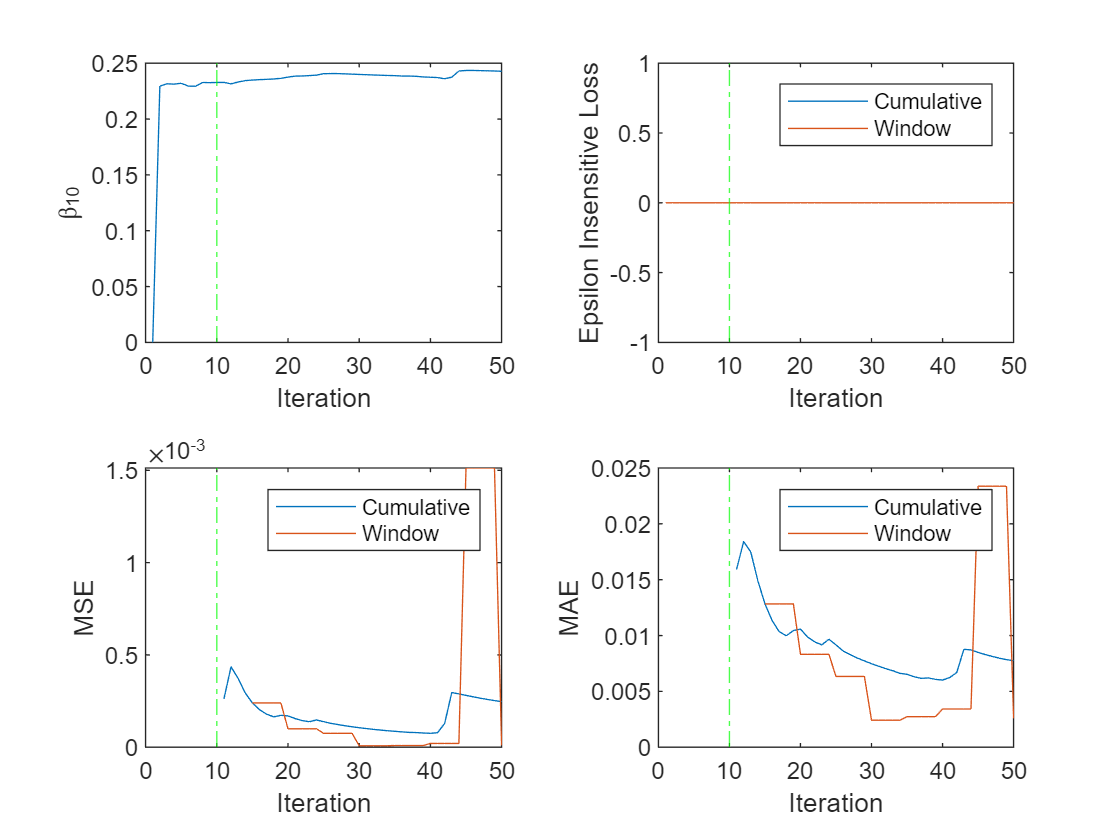


tiledlayout(2,2)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
nexttile
h = plot(ei.Variables);
xlim([0 nchunk])
ylabel('Epsilon Insensitive Loss')
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,ei.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mae.Variables);
xlim([0 nchunk])
ylabel('MAE')
xline(mdl_Linear_VdRul_fitrlinear_inc.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mae.Properties.VariableNames)
xlabel('Iteration')


%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc,Xtrain_all);
y_predict = [ y_predict ; y_predict(end) ; y_predict(end) ];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc = 8.8043

diff_percentage_all_inc = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc = 252×1
    7.2858
    8.9884
    9.7887
   11.0623
   11.8331
    2.3044
    1.9611
    2.0823
    1.0112
    0.1988


diff_percentage_avg_all_inc = mean(diff_percentage_all_inc,1)

diff_percentage_avg_all_inc = 9.2998

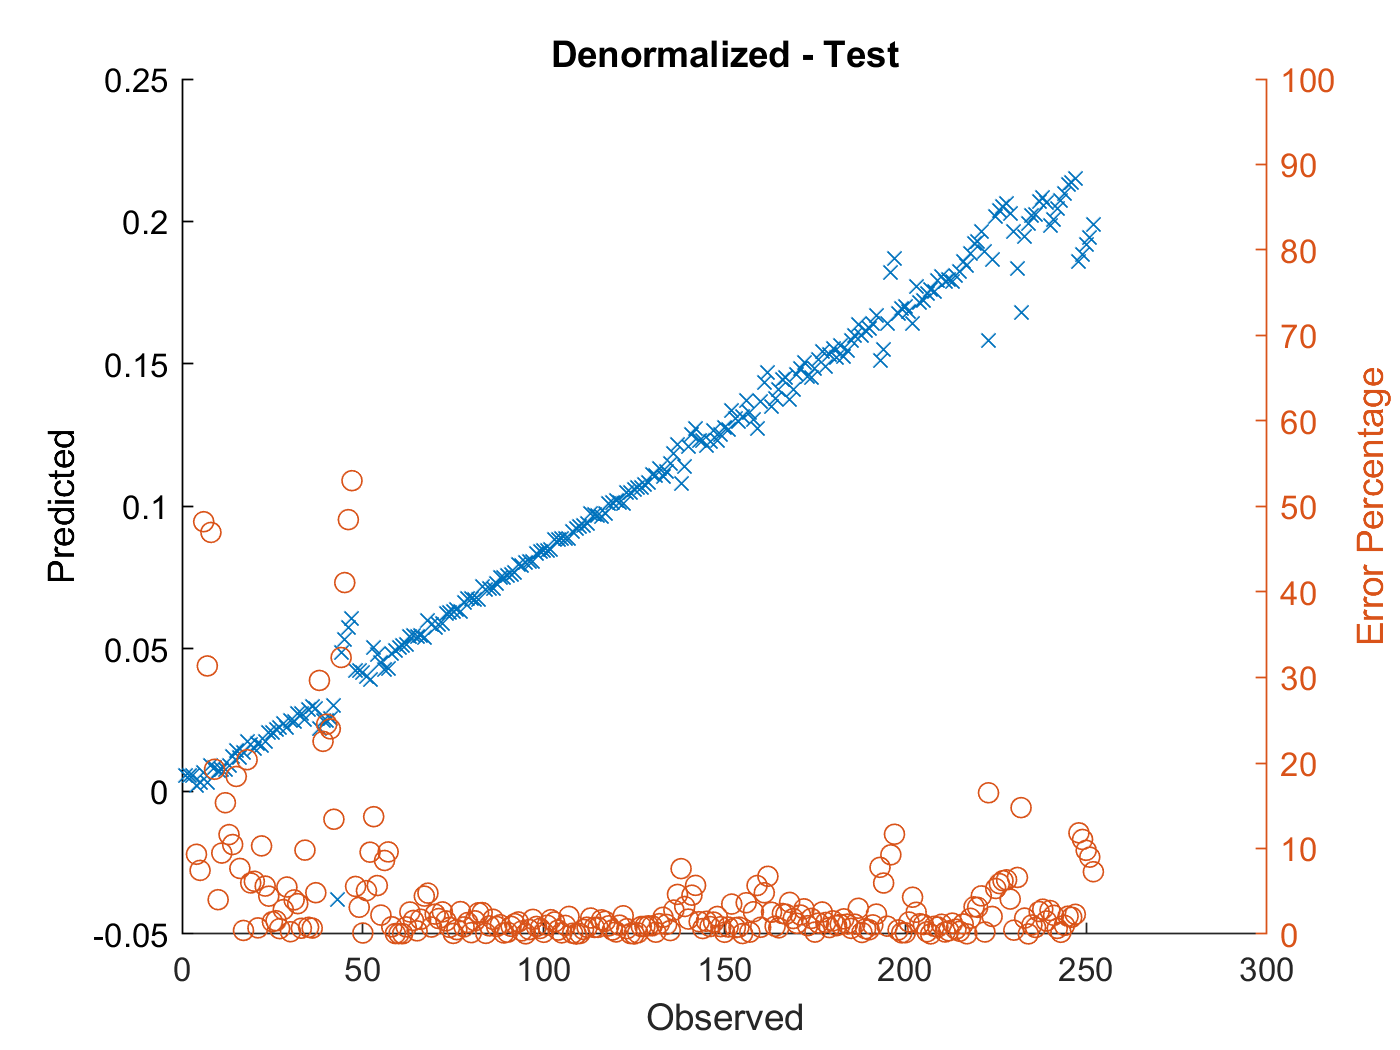

figure
hold on
plot(Ytrain_all,y_predict,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_all,diff_percentage_all_inc,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

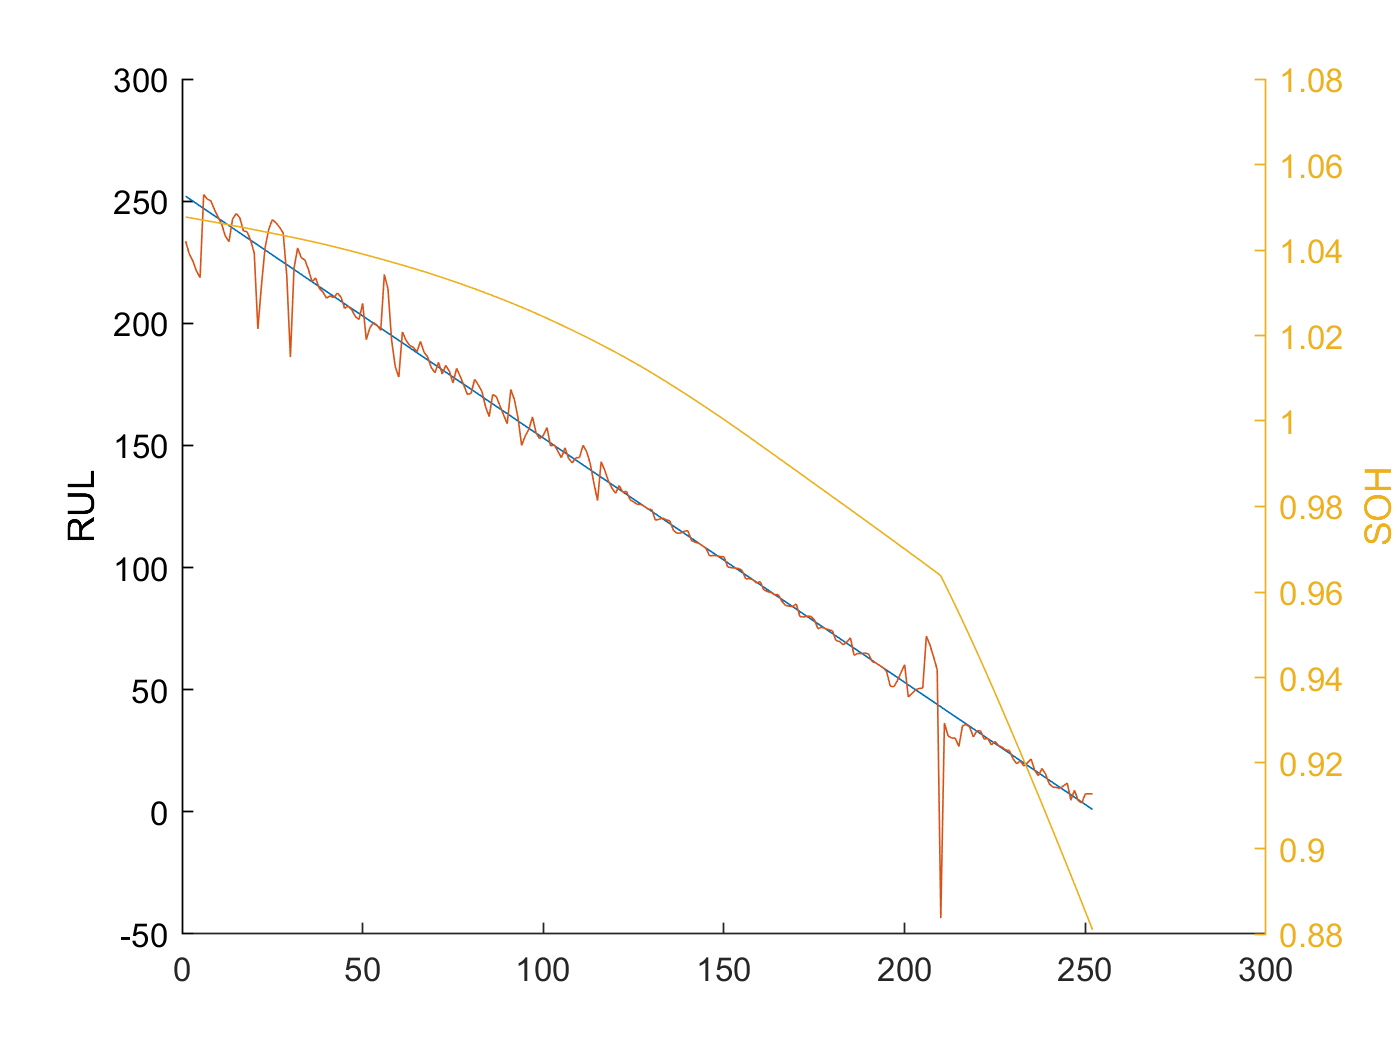


figure, hold on
plot(Y_test_RUL_test1)
plot(Y_predict)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

## 점진적 학습 - 과거데이타에서 실제로는 정확한 RUL을 얻을 수 없다. 자기가 예측한 값으로 모델 업데이트. 러닝레이트를 줄여야 한다.


maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' maemetric})

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc1 = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.002, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' maemetric}...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc1

mdl_Linear_VdRul_fitrlinear_inc1 =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [2×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc1.Beta'

ans =    -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824



y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp =     0.3864
    0.3818
    0.3792
    0.3758
    0.3734


y_predict = y_predict_temp;
for j = 2:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend   
    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc1 = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc1, ...
        Xtrain(idx,:), ...
        y_predict_temp); % 그래나 실제y값을 알기히들다. 
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc1,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc1.Beta'
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp]
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"MeanSquaredError",:};
    mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc1.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc1.Beta(10);
end

idx =      6     7     8     9    10


ans =    -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4950    0.5662    0.4575    0.2428    0.0504   -0.0923   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans =     0.2103    0.3725   -0.1622
    0.2094    0.3709   -0.1615
    0.2085    0.3702   -0.1617
    0.2077    0.3671   -0.1594
    0.2068    0.3645   -0.1577


idx =     11    12    13    14    15


ans =    -0.4299   -0.2471   -0.0564    0.0360    0.1613    0.3305    0.4950    0.5662    0.4575    0.2428    0.0504   -0.0923   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans =     0.2060    0.3654   -0.1594
    0.2051    0.3614   -0.1563
    0.2043    0.3594   -0.1551
    0.2034    0.3675   -0.1640
    0.2026    0.3694   -0.1669


idx =     16    17    18    19    20


ans =    -0.4299   -0.2471   -0.0564    0.0361    0.1614    0.3305    0.4950    0.5662    0.4576    0.2428    0.0504   -0.0923   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans =     0.2017    0.3573   -0.1556
    0.2009    0.3526   -0.1517
    0.2000    0.3523   -0.1523
    0.1991    0.3493   -0.1502
    0.1983    0.3447   -0.1464


idx =     21    22    23    24    25


ans =    -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0923   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1974    0.3533   -0.1558
    0.1966    0.3692   -0.1726
    0.1957    0.3825   -0.1868
    0.1949    0.3891   -0.1942
    0.1940    0.3926   -0.1986


idx =     26    27    28    29    30


ans =    -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1932    0.3932   -0.2000
    0.1923    0.3916   -0.1993
    0.1915    0.3896   -0.1982
    0.1906    0.3741   -0.1835
    0.1897    0.3451   -0.1553


idx =     31    32    33    34    35


ans =    -0.4299   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4950    0.5663    0.4576    0.2428    0.0504   -0.0923   -0.0770   -0.0033    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1889    0.3291   -0.1402
    0.1880    0.3362   -0.1482
    0.1872    0.3328   -0.1456
    0.1863    0.3320   -0.1457
    0.1855    0.3286   -0.1432


idx =     36    37    38    39    40


ans =    -0.4299   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4950    0.5663    0.4576    0.2429    0.0504   -0.0923   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1846    0.3268   -0.1422
    0.1838    0.3281   -0.1443
    0.1829    0.3245   -0.1416
    0.1821    0.3231   -0.1411
    0.1812    0.3209   -0.1397


idx =     41    42    43    44    45


ans =    -0.4299   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4950    0.5663    0.4576    0.2429    0.0504   -0.0923   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1803    0.3192   -0.1388
    0.1795    0.3185   -0.1390
    0.1786    0.3202   -0.1416
    0.1778    0.3187   -0.1410
    0.1769    0.3147   -0.1378


idx =     46    47    48    49    50


ans =    -0.4298   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4951    0.5663    0.4576    0.2429    0.0504   -0.0922   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1761    0.3147   -0.1386
    0.1752    0.3134   -0.1382
    0.1744    0.3110   -0.1367
    0.1735    0.3099   -0.1364
    0.1726    0.3158   -0.1431


idx =     51    52    53    54    55


ans =    -0.4299   -0.2470   -0.0564    0.0361    0.1614    0.3306    0.4950    0.5663    0.4576    0.2429    0.0504   -0.0923   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1718    0.3210   -0.1492
    0.1709    0.3253   -0.1544
    0.1701    0.3272   -0.1571
    0.1692    0.3263   -0.1571
    0.1684    0.3244   -0.1560


idx =     56    57    58    59    60


ans =    -0.4298   -0.2470   -0.0563    0.0361    0.1615    0.3306    0.4951    0.5663    0.4576    0.2429    0.0505   -0.0922   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1675    0.3213   -0.1537
    0.1667    0.3162   -0.1496
    0.1658    0.2978   -0.1320
    0.1650    0.2884   -0.1234
    0.1641    0.2845   -0.1204


idx =     61    62    63    64    65


ans =    -0.4298   -0.2469   -0.0563    0.0362    0.1615    0.3306    0.4951    0.5664    0.4577    0.2429    0.0505   -0.0922   -0.0770   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1632    0.2837   -0.1204
    0.1624    0.2807   -0.1183
    0.1615    0.2789   -0.1173
    0.1607    0.2782   -0.1176
    0.1598    0.2766   -0.1168


idx =     66    67    68    69    70


ans =    -0.4298   -0.2469   -0.0563    0.0362    0.1615    0.3307    0.4951    0.5664    0.4577    0.2430    0.0505   -0.0922   -0.0769   -0.0033    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1590    0.2728   -0.1138
    0.1581    0.2689   -0.1108
    0.1573    0.2673   -0.1100
    0.1564    0.2635   -0.1071
    0.1556    0.2616   -0.1061


idx =     71    72    73    74    75


ans =    -0.4297   -0.2469   -0.0563    0.0362    0.1615    0.3307    0.4951    0.5664    0.4577    0.2430    0.0505   -0.0922   -0.0769   -0.0032    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1547    0.2605   -0.1058
    0.1538    0.2564   -0.1026
    0.1530    0.2595   -0.1065
    0.1521    0.2575   -0.1053
    0.1513    0.2533   -0.1020


idx =     76    77    78    79    80


ans =    -0.4297   -0.2469   -0.0562    0.0362    0.1615    0.3307    0.4952    0.5664    0.4577    0.2430    0.0505   -0.0921   -0.0769   -0.0032    0.1399   -0.0316    1.0318    0.2709   -0.4946   -0.4824


ans =     0.1504    0.2543   -0.1039
    0.1496    0.2515   -0.1020
    0.1487    0.2482   -0.0995
    0.1479    0.2450   -0.0971
    0.1470    0.2454   -0.0984


idx =     81    82    83    84    85


ans =    -0.4297   -0.2469   -0.0562    0.0363    0.1616    0.3307    0.4952    0.5664    0.4577    0.2430    0.0506   -0.0921   -0.0769   -0.0032    0.1400   -0.0316    1.0318    0.2709   -0.4946   -0.4823


ans =     0.1462    0.2460   -0.0999
    0.1453    0.2440   -0.0988
    0.1444    0.2417   -0.0973
    0.1436    0.2363   -0.0927
    0.1427    0.2327   -0.0900


idx = 1×5
    86    87    88    89    90


ans = 1×20
   -0.4297   -0.2468   -0.0562    0.0363    0.1616    0.3307    0.4952    0.5664    0.4578    0.2430    0.0506   -0.0921   -0.0769   -0.0032    0.1400   -0.0316    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1419    0.2328   -0.0909
    0.1410    0.2320   -0.0910
    0.1402    0.2287   -0.0886
    0.1393    0.2255   -0.0862
    0.1385    0.2224   -0.0839


idx = 1×5
    91    92    93    94    95


ans = 1×20
   -0.4296   -0.2468   -0.0562    0.0363    0.1616    0.3308    0.4952    0.5665    0.4578    0.2430    0.0506   -0.0921   -0.0769   -0.0032    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1376    0.2195   -0.0819
    0.1368    0.2159   -0.0791
    0.1359    0.2094   -0.0735
    0.1350    0.1997   -0.0646
    0.1342    0.2030   -0.0689


idx = 1×5
    96    97    98    99   100


ans = 1×20
   -0.4296   -0.2468   -0.0561    0.0363    0.1616    0.3308    0.4952    0.5665    0.4578    0.2431    0.0506   -0.0921   -0.0768   -0.0031    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1333    0.1930   -0.0597
    0.1325    0.1974   -0.0649
    0.1316    0.1916   -0.0600
    0.1308    0.1896   -0.0589
    0.1299    0.1908   -0.0609


idx = 1×5
   101   102   103   104   105


ans = 1×20
   -0.4296   -0.2468   -0.0561    0.0363    0.1617    0.3308    0.4953    0.5665    0.4578    0.2431    0.0506   -0.0920   -0.0768   -0.0031    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1291    0.1921   -0.0630
    0.1282    0.1856   -0.0574
    0.1274    0.1860   -0.0587
    0.1265    0.1838   -0.0573
    0.1256    0.1814   -0.0558


idx = 1×5
   106   107   108   109   110


ans = 1×20
   -0.4296   -0.2467   -0.0561    0.0364    0.1617    0.3308    0.4953    0.5665    0.4578    0.2431    0.0507   -0.0920   -0.0768   -0.0031    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1248    0.1801   -0.0554
    0.1239    0.1764   -0.0524
    0.1231    0.1747   -0.0517
    0.1222    0.1766   -0.0544
    0.1214    0.1767   -0.0554


idx = 1×5
   111   112   113   114   115


ans = 1×20
   -0.4296   -0.2467   -0.0561    0.0364    0.1617    0.3308    0.4953    0.5665    0.4579    0.2431    0.0507   -0.0920   -0.0768   -0.0031    0.1400   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1205    0.1754   -0.0549
    0.1197    0.1731   -0.0534
    0.1188    0.1688   -0.0500
    0.1179    0.1619   -0.0440
    0.1171    0.1558   -0.0387


idx = 1×5
   116   117   118   119   120


ans = 1×20
   -0.4295   -0.2467   -0.0561    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2431    0.0507   -0.0920   -0.0768   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1162    0.1524   -0.0362
    0.1154    0.1494   -0.0340
    0.1145    0.1457   -0.0312
    0.1137    0.1431   -0.0294
    0.1128    0.1413   -0.0284


idx = 1×5
   121   122   123   124   125


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0768   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1120    0.1421   -0.0301
    0.1111    0.1396   -0.0285
    0.1103    0.1400   -0.0298
    0.1094    0.1370   -0.0276
    0.1085    0.1362   -0.0277


idx = 1×5
   126   127   128   129   130


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1077    0.1353   -0.0276
    0.1068    0.1353   -0.0284
    0.1060    0.1345   -0.0285
    0.1051    0.1336   -0.0284
    0.1043    0.1334   -0.0291


idx = 1×5
   131   132   133   134   135


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.1034    0.1332   -0.0298
    0.1026    0.1335   -0.0309
    0.1017    0.1340   -0.0323
    0.1009    0.1333   -0.0324
    0.1000    0.1329   -0.0329


idx = 1×5
   136   137   138   139   140


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0991    0.1325   -0.0333
    0.0983    0.1314   -0.0331
    0.0974    0.1314   -0.0340
    0.0966    0.1321   -0.0355
    0.0957    0.1323   -0.0366


idx = 1×5
   141   142   143   144   145


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0949    0.1322   -0.0373
    0.0940    0.1316   -0.0376
    0.0932    0.1312   -0.0380
    0.0923    0.1303   -0.0380
    0.0915    0.1293   -0.0379


idx = 1×5
   146   147   148   149   150


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0906    0.1297   -0.0391
    0.0897    0.1298   -0.0401
    0.0889    0.1297   -0.0408
    0.0880    0.1294   -0.0413
    0.0872    0.1293   -0.0421


idx = 1×5
   151   152   153   154   155


ans = 1×20
   -0.4295   -0.2467   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0863    0.1289   -0.0426
    0.0855    0.1286   -0.0431
    0.0846    0.1284   -0.0438
    0.0838    0.1282   -0.0445
    0.0829    0.1275   -0.0446


idx = 1×5
   156   157   158   159   160


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0364    0.1618    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0821    0.1270   -0.0449
    0.0812    0.1271   -0.0459
    0.0803    0.1266   -0.0463
    0.0795    0.1254   -0.0459
    0.0786    0.1260   -0.0474


idx = 1×5
   161   162   163   164   165


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0778    0.1261   -0.0483
    0.0769    0.1255   -0.0485
    0.0761    0.1251   -0.0490
    0.0752    0.1243   -0.0491
    0.0744    0.1243   -0.0500


idx = 1×5
   166   167   168   169   170


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0507   -0.0919   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0735    0.1235   -0.0500
    0.0726    0.1219   -0.0492
    0.0718    0.1216   -0.0498
    0.0709    0.1214   -0.0505
    0.0701    0.1223   -0.0523


idx = 1×5
   171   172   173   174   175


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0919   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0692    0.1227   -0.0534
    0.0684    0.1225   -0.0541
    0.0675    0.1228   -0.0553
    0.0667    0.1227   -0.0561
    0.0658    0.1215   -0.0556


idx = 1×5
   176   177   178   179   180


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0650    0.1183   -0.0534
    0.0641    0.1189   -0.0548
    0.0632    0.1184   -0.0551
    0.0624    0.1180   -0.0556
    0.0615    0.1175   -0.0560


idx = 1×5
   181   182   183   184   185


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0607    0.1168   -0.0561
    0.0598    0.1164   -0.0566
    0.0590    0.1152   -0.0562
    0.0581    0.1163   -0.0581
    0.0573    0.1178   -0.0605


idx = 1×5
   186   187   188   189   190


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0507   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0564    0.1191   -0.0627
    0.0556    0.1198   -0.0643
    0.0547    0.1197   -0.0650
    0.0538    0.1200   -0.0661
    0.0530    0.1196   -0.0666


idx = 1×5
   191   192   193   194   195


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0521    0.1196   -0.0675
    0.0513    0.1191   -0.0678
    0.0504    0.1182   -0.0678
    0.0496    0.1173   -0.0678
    0.0487    0.1160   -0.0672


idx = 1×5
   196   197   198   199   200


ans = 1×20
   -0.4294   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0479    0.1147   -0.0668
    0.0470    0.1143   -0.0673
    0.0462    0.1167   -0.0706
    0.0453    0.1197   -0.0744
    0.0444    0.1226   -0.0782


idx = 1×5
   201   202   203   204   205


ans = 1×20
   -0.4295   -0.2466   -0.0560    0.0364    0.1617    0.3309    0.4953    0.5666    0.4579    0.2432    0.0507   -0.0920   -0.0767   -0.0031    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0436    0.1248   -0.0813
    0.0427    0.1261   -0.0834
    0.0419    0.1275   -0.0857
    0.0410    0.1281   -0.0870
    0.0402    0.1282   -0.0880


idx = 1×5
   206   207   208   209   210


ans = 1×20
   -0.4294   -0.2466   -0.0560    0.0365    0.1618    0.3309    0.4954    0.5666    0.4579    0.2432    0.0508   -0.0919   -0.0767   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0393    0.1285   -0.0892
    0.0385    0.1252   -0.0867
    0.0376    0.1208   -0.0832
    0.0368    0.1159   -0.0792
    0.0359    0.0235    0.0124


idx = 1×5
   211   212   213   214   215


ans = 1×20
   -0.4293   -0.2465   -0.0558    0.0366    0.1619    0.3311    0.4955    0.5667    0.4581    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0350    0.0256    0.0095
    0.0342    0.0210    0.0132
    0.0333    0.0202    0.0132
    0.0325    0.0202    0.0123
    0.0316    0.0171    0.0145


idx = 1×5
   216   217   218   219   220


ans = 1×20
   -0.4293   -0.2465   -0.0558    0.0366    0.1619    0.3311    0.4955    0.5668    0.4581    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0308    0.0182    0.0125
    0.0299    0.0187    0.0112
    0.0291    0.0178    0.0113
    0.0282    0.0143    0.0139
    0.0274    0.0165    0.0109


idx = 1×5
   221   222   223   224   225


ans = 1×20
   -0.4293   -0.2464   -0.0558    0.0366    0.1619    0.3311    0.4955    0.5668    0.4581    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0265    0.0163    0.0101
    0.0256    0.0135    0.0122
    0.0248    0.0137    0.0111
    0.0239    0.0114    0.0125
    0.0231    0.0126    0.0105


idx = 1×5
   226   227   228   229   230


ans = 1×20
   -0.4292   -0.2464   -0.0558    0.0366    0.1619    0.3311    0.4955    0.5668    0.4581    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0222    0.0127    0.0095
    0.0214    0.0120    0.0093
    0.0205    0.0112    0.0094
    0.0197    0.0109    0.0088
    0.0188    0.0080    0.0108


idx = 1×5
   231   232   233   234   235


ans = 1×20
   -0.4292   -0.2464   -0.0558    0.0366    0.1619    0.3311    0.4955    0.5668    0.4581    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0179    0.0081    0.0099
    0.0171    0.0090    0.0080
    0.0162    0.0072    0.0090
    0.0154    0.0084    0.0070
    0.0145    0.0097    0.0048


idx = 1×5
   236   237   238   239   240


ans = 1×20
   -0.4292   -0.2464   -0.0558    0.0367    0.1619    0.3311    0.4955    0.5668    0.4581    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0137    0.0076    0.0061
    0.0128    0.0057    0.0071
    0.0120    0.0083    0.0037
    0.0111    0.0063    0.0048
    0.0103    0.0029    0.0074


idx = 1×5
   241   242   243   244   245


ans = 1×20
   -0.4292   -0.2464   -0.0558    0.0367    0.1620    0.3311    0.4955    0.5668    0.4581    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0094    0.0041    0.0053
    0.0085    0.0039    0.0046
    0.0077    0.0036    0.0041
    0.0068    0.0046    0.0023
    0.0060    0.0054    0.0005


idx = 1×5
   246   247   248   249   250


ans = 1×20
   -0.4292   -0.2464   -0.0558    0.0367    0.1620    0.3311    0.4955    0.5668    0.4581    0.2433    0.0509   -0.0918   -0.0766   -0.0030    0.1401   -0.0315    1.0318    0.2709   -0.4946   -0.4823


ans = 5×3
    0.0051    0.0032    0.0020
    0.0043    0.0067   -0.0024
    0.0034    0.0030    0.0004
    0.0026    0.0021    0.0004
    0.0017    0.0054   -0.0036


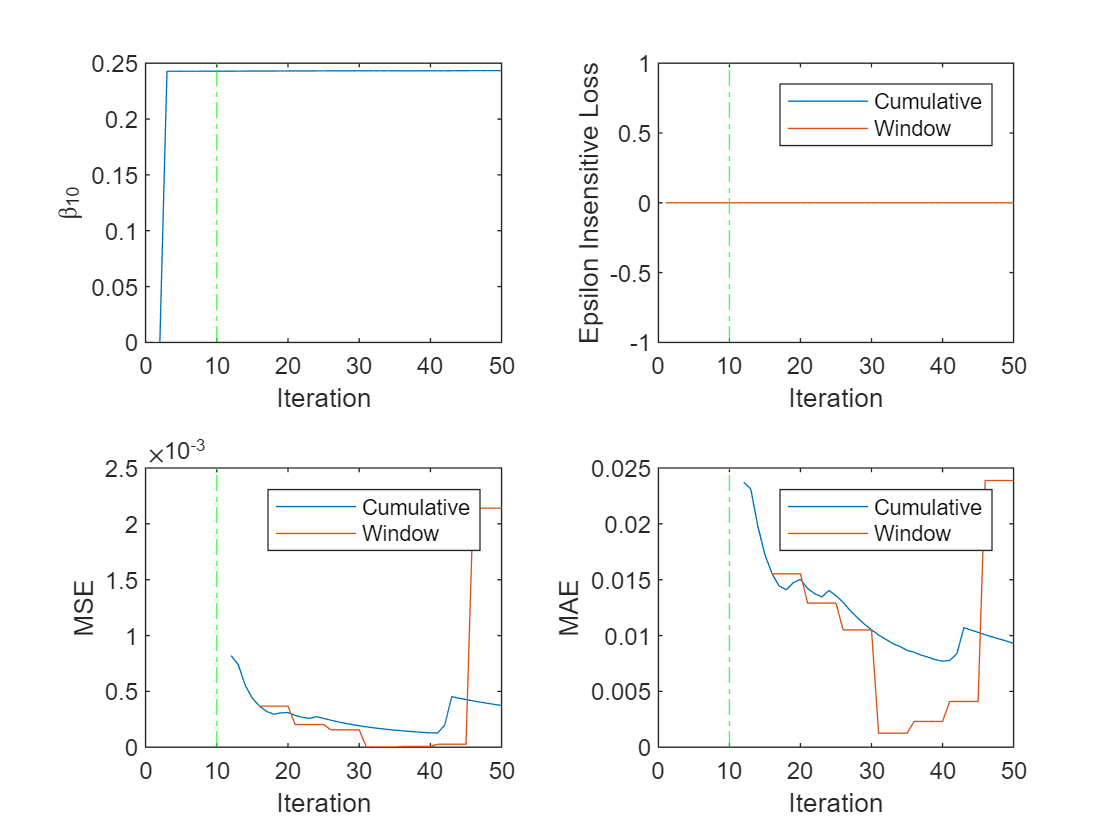


tiledlayout(2,2)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
nexttile
h = plot(ei.Variables);
xlim([0 nchunk])
ylabel('Epsilon Insensitive Loss')
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,ei.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mae.Variables);
xlim([0 nchunk])
ylabel('MAE')
xline(mdl_Linear_VdRul_fitrlinear_inc1.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mae.Properties.VariableNames)
xlabel('Iteration')


%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc1,Xtrain_all);
y_predict = [ y_predict ; y_predict(end) ; y_predict(end) ];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc1 = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc1 = 107.8864

diff_percentage_all_inc1 = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc1 = 252×1
   79.7775
   78.3592
   77.8800
   76.9676
   76.5527
   76.8444
   76.7987
   77.1992
   76.4235
   75.9126


diff_percentage_avg_all_inc1 = mean(diff_percentage_all_inc1,1)

diff_percentage_avg_all_inc1 = 72.4621

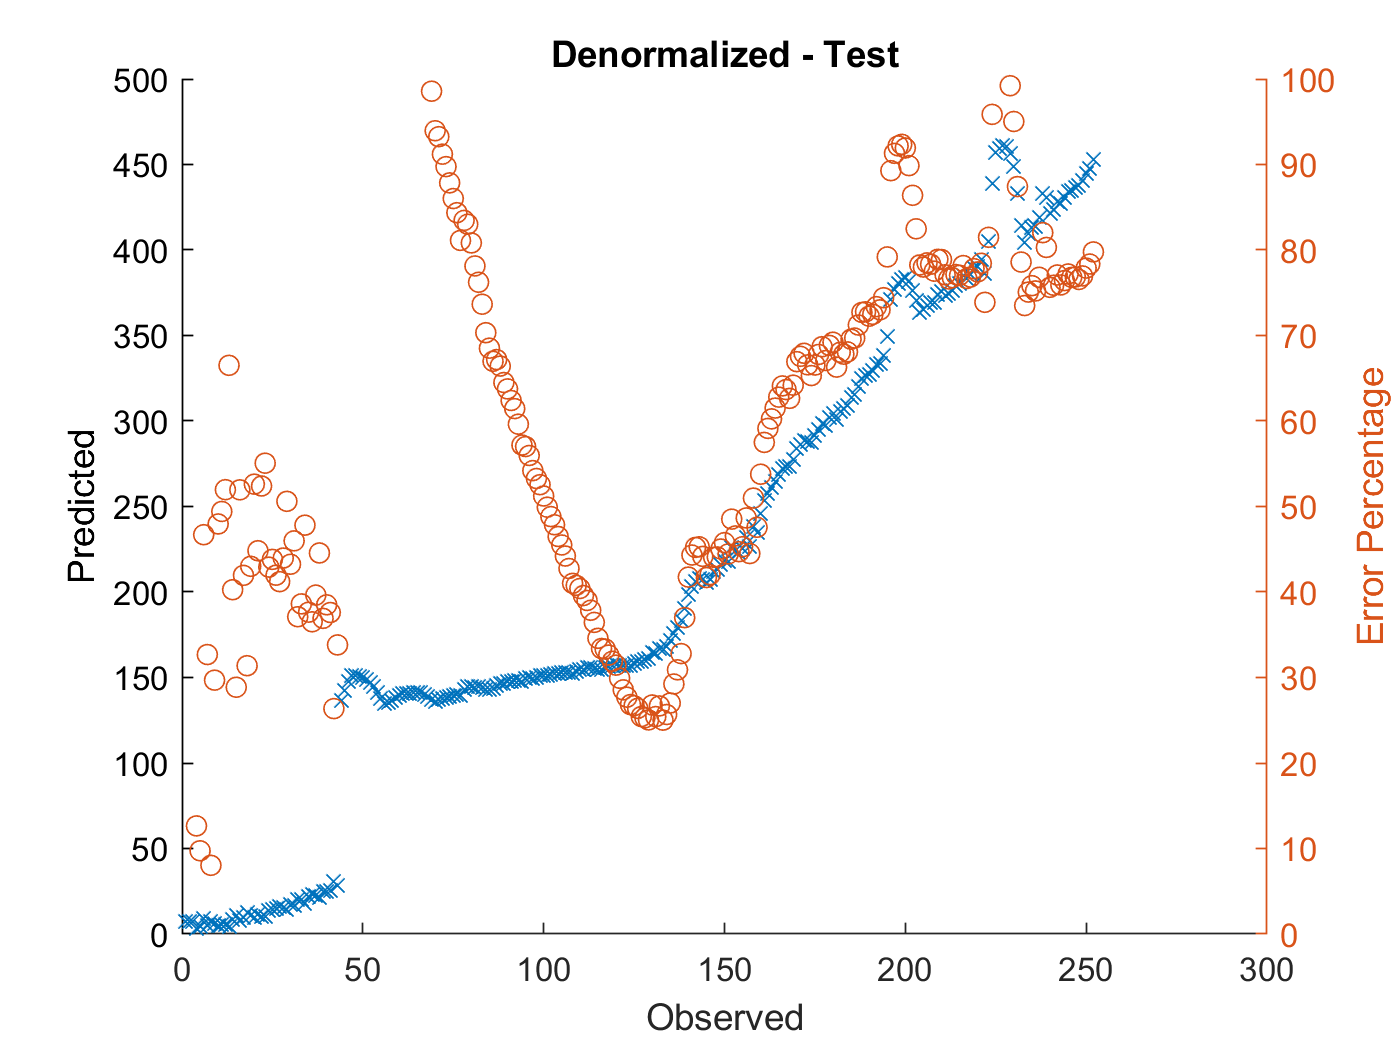

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_all,diff_percentage_all_inc1,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

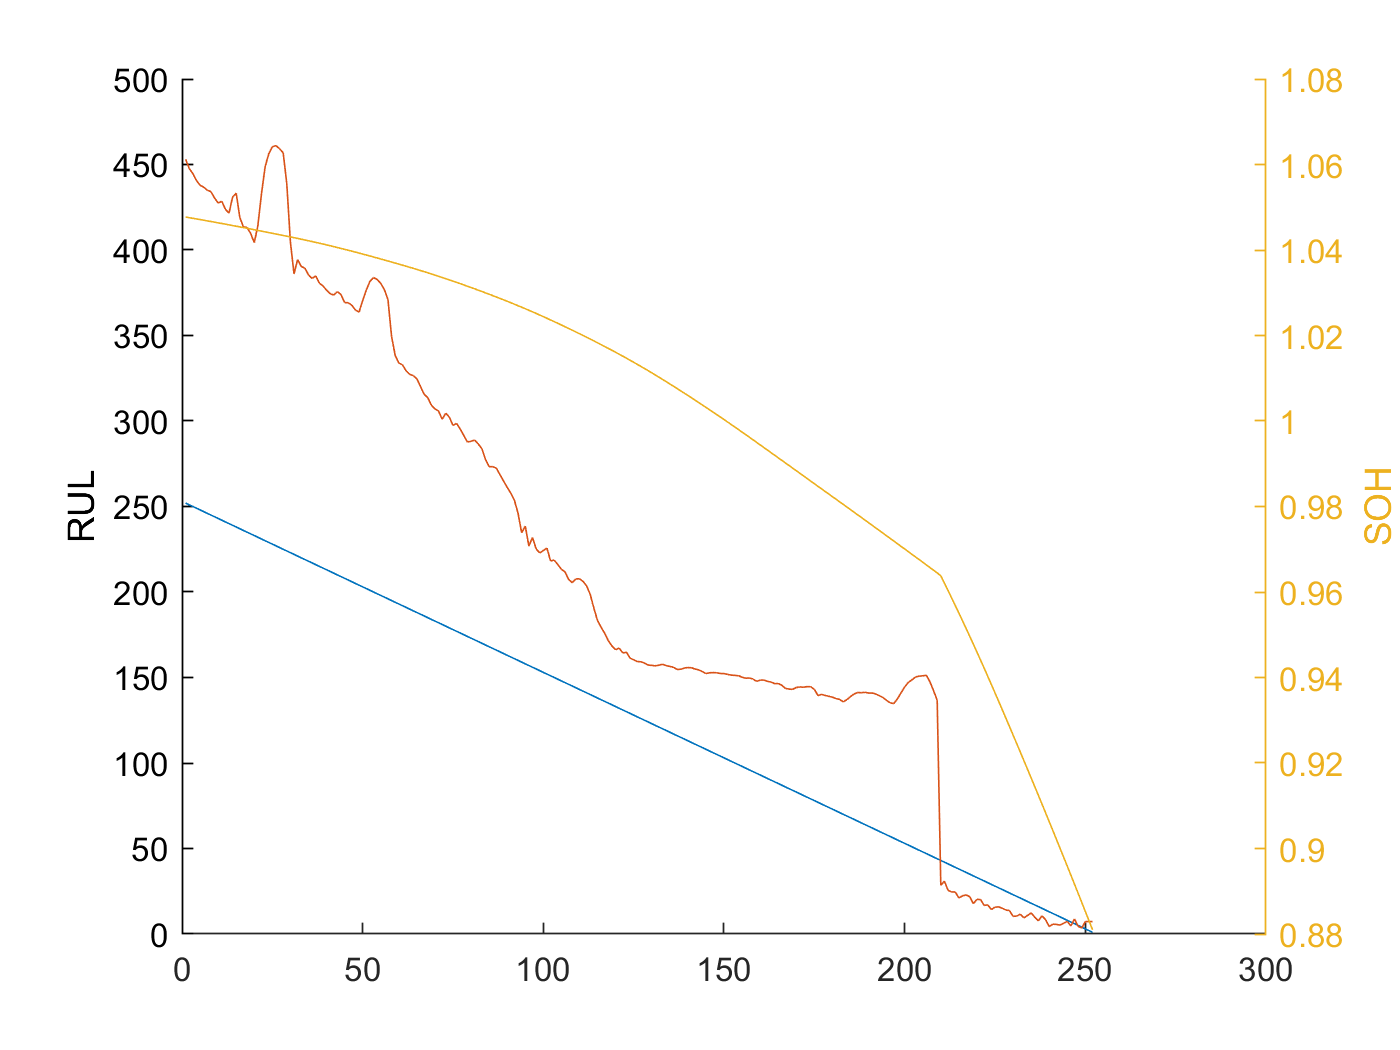



figure, hold on
plot(Y_test_RUL_test1)
plot(Y_predict)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

## 점진적 학습 - 과거데이타에서 실제로는 정확한 RUL을 얻을 수 없다. 자기가 예측한 값과 가장 비슷한 패턴의 다른 데이타로 모델 업데이트. 러닝레이트를 줄여야 한다.




maefcn = @(z,zfit)abs(z - zfit);
maemetric = struct("MeanAbsoluteError",maefcn);

% Mdl = incrementalRegressionLinear('Epsilon',0.05, ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',1000,'MetricsWindowSize',500, ...
%     'Metrics',{'epsiloninsensitive' 'mse_val' maemetric})

% Mdl = incrementalRegressionLinear(  ...
%     'Solver','sgd','Lambda',0.001,'BatchSize',20,'LearnRate',0.002, ...
%     'Standardize',false, ...
%     'MetricsWarmupPeriod',100,'MetricsWindowSize',50, ...
%     'Learner','leastsquares', ...
%     'Metrics',{ 'mse' maemetric})

% 'LearnRate',0.002 => 적응속도가 느리다.
% 'LearnRate',0.1 => 뒤로 갈수록 정확해 진다.
mdl_Linear_VdRul_fitrlinear_inc2 = incrementalLearner(mdl_Linear_VdRul_fitrlinear, ...
    'Solver','sgd','Lambda',0.001,'BatchSize',5,'LearnRate',0.1, ...
    'Standardize',false, ...
    'MetricsWarmupPeriod',50,'MetricsWindowSize',25, ...
    'Metrics',{ 'mse' maemetric}...
    );
mdl_Linear_VdRul_fitrlinear

mdl_Linear_VdRul_fitrlinear =   RegressionLinear
         ResponseName: 'Y'
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
               Lambda: 2.6064e-05
              Learner: 'leastsquares'


  Properties, Methods


mdl_Linear_VdRul_fitrlinear_inc2

mdl_Linear_VdRul_fitrlinear_inc2 =   incrementalRegressionLinear

               IsWarm: 0
              Metrics: [2×2 table]
    ResponseTransform: 'none'
                 Beta: [20×1 double]
                 Bias: -1.0687
              Learner: 'leastsquares'


  Properties, Methods


n = numel(ytrain);
% Preallocation
numObsPerChunk = 5; %50;
nchunk = floor(n/numObsPerChunk);
ei = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mse_val = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
mae = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);
beta10 = zeros(nchunk,1);    
y_predict = []; %zeros();
% Incremental fitting
rng("default"); % For reproducibility
mdl_Linear_VdRul_fitrlinear_inc2.Beta'

ans = 1×20
   -0.4300   -0.2471   -0.0565    0.0360    0.1613    0.3305    0.4949    0.5662    0.4575    0.2428    0.0503   -0.0924   -0.0771   -0.0034    0.1398   -0.0317    1.0318    0.2709   -0.4946   -0.4824




y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear, Xtrain(1:numObsPerChunk,:))

y_predict_temp = 5×1
    0.3864
    0.3818
    0.3792
    0.3758
    0.3734


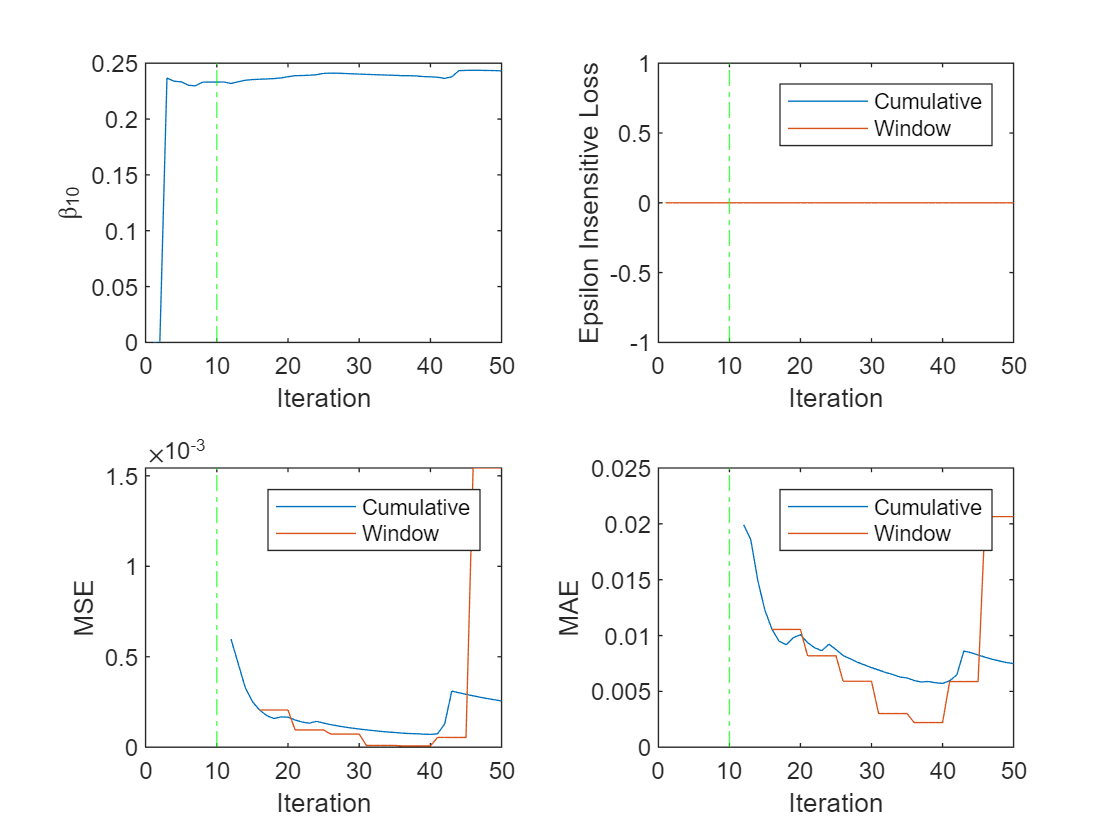

y_predict = y_predict_temp;
for j = 2:nchunk
    ibegin = min(n,numObsPerChunk*(j-1) + 1);
    iend   = min(n,numObsPerChunk*j);
    idx = ibegin:iend   ;


    % y_update = ytrain(idx);
    y_update = ( ytrain(idx) + y_predict_temp ) /2 ;

    % 문제는 원하는 값을 우리가 알고 있다고 가정하고 다시 Fit을 한다.
    mdl_Linear_VdRul_fitrlinear_inc2 = updateMetricsAndFit( ...
        mdl_Linear_VdRul_fitrlinear_inc2, ...
        Xtrain(idx,:), ...
        y_update); %  
    y_predict_temp = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain(idx,:));
    mdl_Linear_VdRul_fitrlinear_inc2.Beta';
    y_predict = [ y_predict ; y_predict_temp ];
    [ytrain(idx) y_predict_temp ytrain(idx)-y_predict_temp];
    %ei{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"EpsilonInsensitiveLoss",:};
    mse_val{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanSquaredError",:};
    mae{j,:} = mdl_Linear_VdRul_fitrlinear_inc2.Metrics{"MeanAbsoluteError",:};
    beta10(j + 1) = mdl_Linear_VdRul_fitrlinear_inc2.Beta(10);
end

tiledlayout(2,2)
nexttile
plot(beta10)
ylabel('\beta_{10}')
xlim([0 nchunk])
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
xlabel('Iteration')
nexttile
h = plot(ei.Variables);
xlim([0 nchunk])
ylabel('Epsilon Insensitive Loss')
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,ei.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mse_val.Variables);
xlim([0 nchunk])
ylabel('MSE')
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mse_val.Properties.VariableNames)
xlabel('Iteration')
nexttile
h = plot(mae.Variables);
xlim([0 nchunk])
ylabel('MAE')
xline(mdl_Linear_VdRul_fitrlinear_inc2.MetricsWarmupPeriod/numObsPerChunk,'g-.')
legend(h,mae.Properties.VariableNames)
xlabel('Iteration')


%yhat_all = predict(mdl_Linear_VdRul_fitrlinear_inc2,Xtrain_all);
y_predict = [ y_predict ; y_predict(end) ; y_predict(end) ];

Y_predict = y_predict * yrate_RUL + ymin_RUL;

rmse_all_inc2 = sqrt( mean((Ytrain_all - Y_predict).^2 ) )

rmse_all_inc2 = 32.3300

diff_percentage_all_inc2 = abs(Ytrain_all - Y_predict)./Ytrain_all.*100

diff_percentage_all_inc2 = 252×1
   79.7775
   78.3592
   77.8800
   76.9676
   76.5527
   36.8410
   36.6355
   36.8861
   35.9517
   35.2789


diff_percentage_avg_all_inc2 = mean(diff_percentage_all_inc2,1)

diff_percentage_avg_all_inc2 = 20.3422

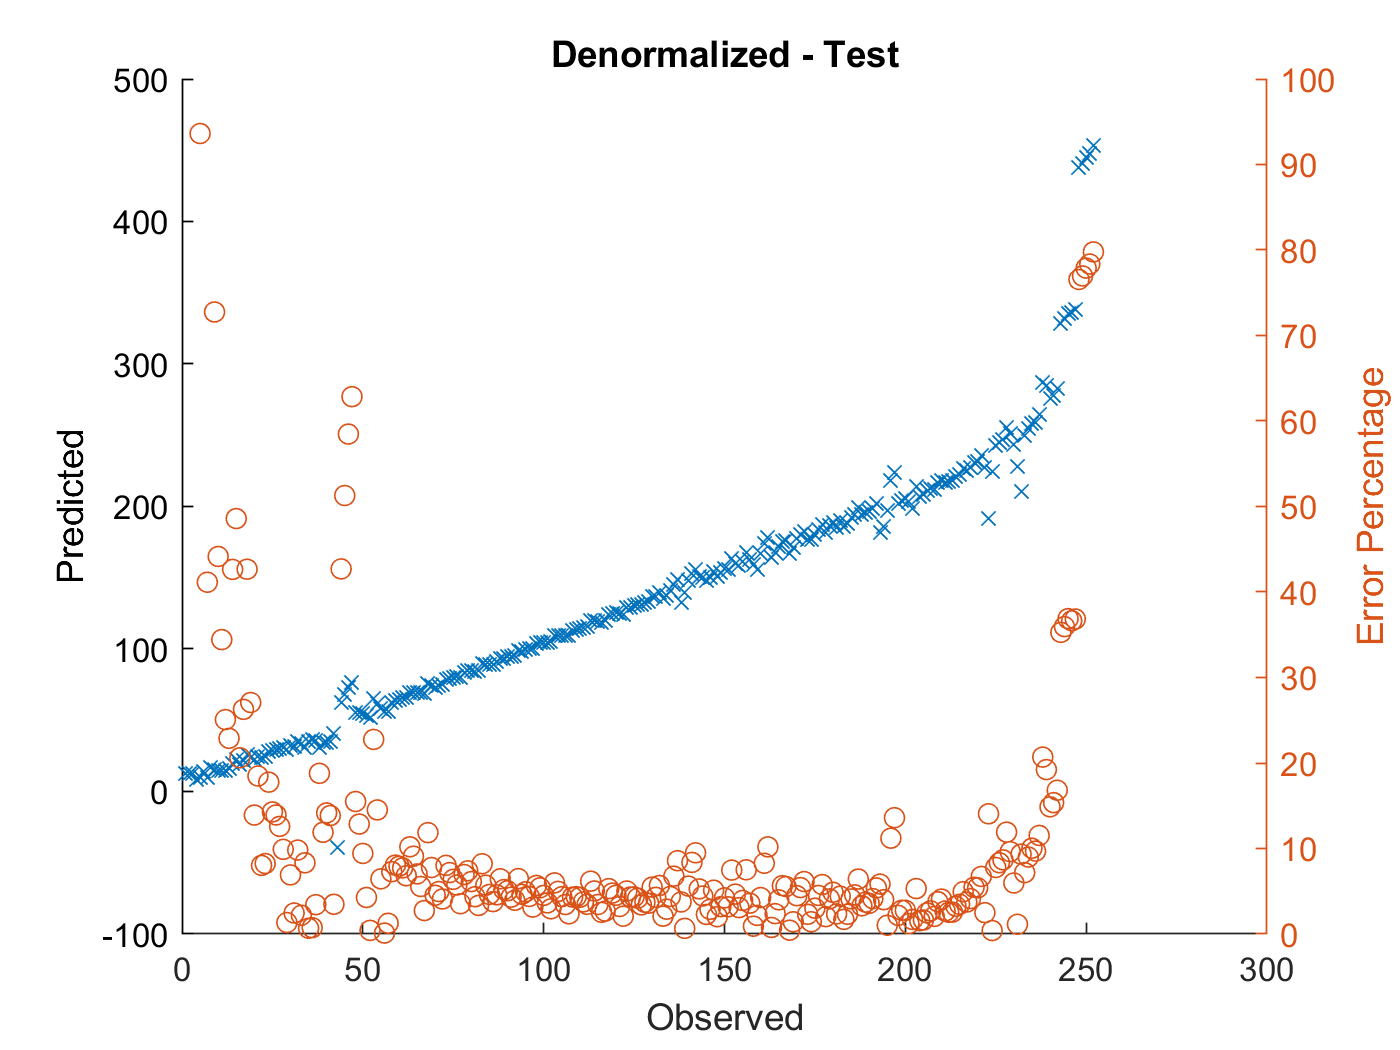

figure
hold on
plot(Ytrain_all,Y_predict,'x')
xlabel("Observed")
ylabel("Predicted")
%xlim([0 1200]), ylim([0 1200])

yyaxis right
ylabel('Error Percentage')
plot(Ytrain_all,diff_percentage_all_inc2,'o');
ylim([0 100])

hold off
title 'Denormalized - Test'

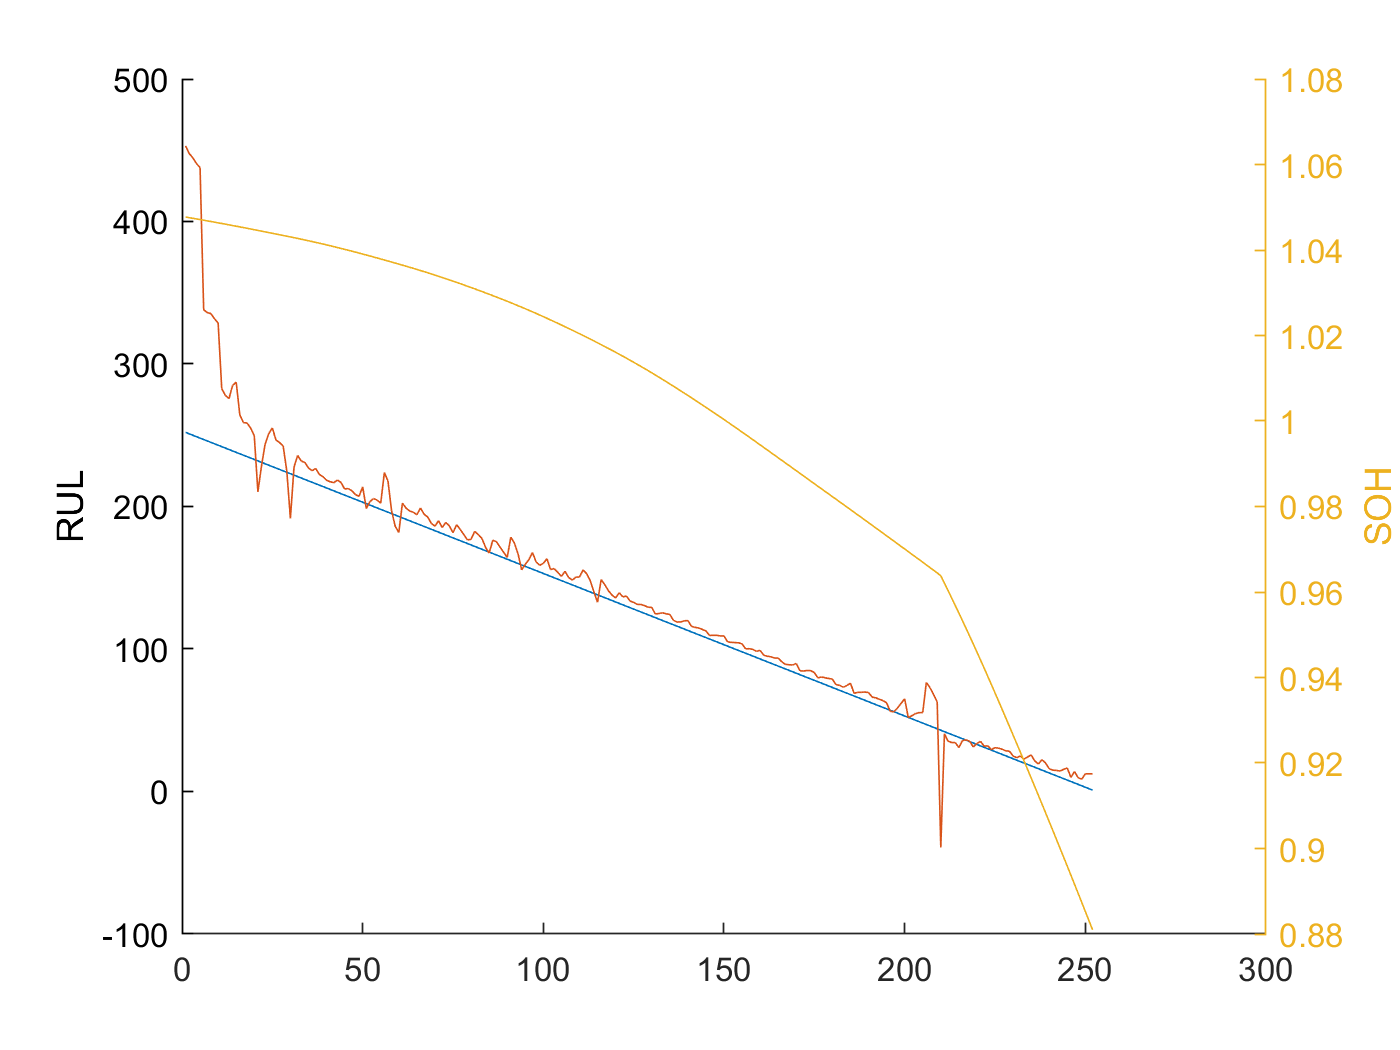



figure, hold on
plot(Y_test_RUL_test1)
plot(Y_predict)
ylabel('RUL')

yyaxis right
ylabel('SOH')
plot(Y_test_SOH_test1)
hold off

## 현재까지의 자기 데이타로 학습/예측 - 실제적이지 않다. - 오차 적음


result_pre_summary = table(rmse_pre,diff_percentage_avg_pre);
result_pre_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_pre_summary

result_pre_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    14.072      5.3963  


## 현재까지의 자기 데이타로 학습/이후 예측 - 오차 큼


result_future_summary = table(rmse_future,diff_percentage_avg_future);
result_future_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_future_summary

result_future_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    132.75      537.33  


## 다른 데이타들로 학습 후 자기 데이타로 예측 - 일반적 시나리오 - 오차 보통


result_all_summary = table(rmse_all,diff_percentage_avg_all);
result_all_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_all_summary

result_all_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    105.73      74.673  


## 기본 모델은 클라우드에서 학습한 것. 점진적 학습. 자신의 미래 RUL을 확신하는 경우 - 오차 적음. 학습비율 크게.


result_all_inc_summary = table(rmse_all_inc,diff_percentage_avg_all_inc);
result_all_inc_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_all_inc_summary

result_all_inc_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    8.8043      9.2998  


## 확실할 수 없다. 5개의 관측으로 모델갱신 후 다음 5개 예측 - 오차 큼 - 학습비율 작게 


result_all_inc1_summary = table(rmse_all_inc1,diff_percentage_avg_all_inc1);
result_all_inc1_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_all_inc1_summary

result_all_inc1_summary = 1×2 table
     RMSE     평균오차비율
    ______    __________

    107.89      72.462  


## 5개의 예측값과 비슷한 다른 데이타의 5개 값을 이용 모델 갱신 -오차 작음


result_all_inc2_summary = table(rmse_all_inc2,diff_percentage_avg_all_inc2);
result_all_inc2_summary.Properties.VariableNames = {'RMSE','평균오차비율'};
result_all_inc2_summary

result_all_inc2_summary = 1×2 table
    RMSE     평균오차비율
    _____    __________

    32.33      20.342  


% http://matlab.izmiran.ru/help/toolbox/nnet/model211.html


p1 = [-1  0 1 0 1 1 -1  0 -1 1 0 1];
t1 = [-1 -1 1 1 1 2  0 -1 -1 0 1 1 ];
net = linearlayer([0 1],0.1)

net =

    Neural Network
 
              name: 'Linear Neural Layer'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 1
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect: tr

[net,y,e,pf] = adapt(net,p1,t1)

net =

    Neural Network
 
              name: 'Linear Neural Layer'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 1
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 3
        sampleTime: 1
 
    connections:
 
       biasConnect: true
      inputConnect: tr

y = 1×12
     0     0     0     0     0     0     0     0     0     0     0     0


e = 1×12
    -1    -1     1     1     1     2     0    -1    -1     0     1     1


pf = 1×12
    -1     0     1     0     1     1    -1     0    -1     1     0     1


%clear mse
mse(e)

ans = 1.0833

% https://kr.mathworks.com/matlabcentral/answers/269435-what-is-the-difference-between-the-regress-function-and-the-fitlm-function
% The key difference is intercept: 1. "fitlm(x,y)" function uses intercept by default 2. "regress(y,x)" function uses no intercept by default (you can add intercept by adding "ones" matrix)

% https://kr.mathworks.com/help/stats/fitrlinear.html
% fitrlinear
% Fit linear regression model to high-dimensional data


%Alternatives for Lower-Dimensional Data
%High-dimensional linear classification and regression models minimize objective functions relatively quickly, but at the cost of some accuracy, the numeric-only predictor variables restriction, and the model must be linear with respect to the parameters. If your predictor data set is low- through medium-dimensional, or contains heterogeneous variables, then you should use the appropriate classification or regression fitting function. To help you decide which fitting function is appropriate for your low-dimensional data set, use this table.

% Model to Fit	Function	Notable Algorithmic Differences
% SVM	
% Binary classification: fitcsvm
% 
% Multiclass classification: fitcecoc
% 
% Regression: fitrsvm
% 
% Computes the Gram matrix of the predictor variables, which is convenient for nonlinear kernel transformations.
% 
% Solves dual problem using SMO, ISDA, or L1 minimization via quadratic programming using quadprog (Optimization Toolbox).
% 
% Linear regression	
% Least-squares without regularization: fitlm
% 
% Regularized least-squares using a lasso penalty: lasso
% 
% Ridge regression: ridge or lasso
% 
% lasso implements cyclic coordinate descent.
% 
% Logistic regression	
% Logistic regression without regularization: fitglm.
% 
% Regularized logistic regression using a lasso penalty: lassoglm
% 
% fitglm implements iteratively reweighted least squares.
% 
% lassoglm implements cyclic coordinate descent.



% https://kr.mathworks.com/help/stats/incrementalregressionlinear.html
% Description
% incrementalRegressionLinear creates an incrementalRegressionLinear model object, which represents an incremental linear model for regression problems. Supported learners include support vector machine (SVM) and least squares.
% 
% Unlike other Statistics and Machine Learning Toolbox™ model objects, incrementalRegressionLinear can be called directly. Also, you can specify learning options, such as performance metrics configurations, parameter values, and the objective solver, before fitting the model to data. After you create an incrementalRegressionLinear object, it is prepared for incremental learning.
% 
% incrementalRegressionLinear is best suited for incremental learning. For a traditional approach to training an SVM or linear regression model (such as creating a model by fitting it to data, performing cross-validation, tuning hyperparameters, and so on), see fitrsvm or fitrlinear.
% 
% 
% https://kr.mathworks.com/help/stats/regressionlinear-class.html
% Construction
% Create a RegressionLinear object by using fitrlinear.